# LTI Systems: Qualitative Analysis of the Step Response  

## Introduction

In this live script, we will illustrate with examples the **qualitative behaviour** of the **step response** for **proper**, **asymptotically stable LTI systems** of first, second and higher order, without or with zeros, varying the position of the poles or the position of the zeros if present.  Furthermore, we will illustrate how to evaluate the **characteristic parameters of the step response** (i.e. rise time, settling time, etc.) using the functions available in MATLAB's **Control System Toolbox**.

clear
clc

## With a Little Help from the 'help' Command!

Here is the documentation, available with the help command, related to the Control System Toolbox function we will use in this live script

help tf

 tf - Transfer function model
    Use tf to create real-valued or complex-valued transfer function models,
    or to convert dynamic system models to transfer function form.

    Creation
      Syntax
        sys = tf(numerator,denominator)
        sys = tf(numerator,denominator,ts)
        sys = tf(numerator,denominator,ltiSys)

        sys = tf(m)

        sys = tf(___,Name,Value)

        sys = tf(ltiSys)
        sys = tf(ltiSys,component)

        s = tf('s')
        z = tf('z',ts)

      Input Arguments
        numerator - Numerator coefficients of the transfer function
          row vector | Ny-by-Nu cell array of row vectors
        


help step

 step - Step response of dynamic system
    step computes the step response to a step change in input value from U
    to U + dU after td time units.

    Syntax
      [y,tOut] = step(sys)
      [y,tOut] = step(sys,t)
      [y,tOut] = step(sys,t,p)
      [y,tOut,x] = step(___)
      [y,tOut,x,ysd] = step(___)
      [y,tOut,x,~,pOut] = step(sys,t,p)

      [y,tOut] = step(___,config)

      step(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      t - Time steps
        positive scalar | two-element vector | vector | 


help RespConfig

 RespConfig - Options for step or impulse responses
    Use a RespConfig object to specify options for plotting step responses
    (step, stepplot), impulse responses (impulse, impulseplot), and initial
    responses (initial and initialplot).

    Creation
      Syntax
        respOpt = RespConfig
        respOpt = RespConfig(Name=Value)

    Properties
      Bias - Baseline input signal value
        0 (default) | scalar | vector | 'u0'
      Amplitude - Input level change
        1 (default) | scalar | vector
      Delay - Step or impulse delay
        0 (default) | nonnegative scalar
      


help stepplot

--- help for controllib.chart.StepPlot ---

 controllib.chart.StepPlot - Plot step response of dynamic system
    The stepplot function plots the step response of a dynamic system model
    and returns a StepPlot chart object.

    Creation
      Syntax
        sp = stepplot(sys)
        sp = stepplot(sys1,sys2,...,sysN)
        sp = stepplot(sys1,LineSpec1,...,sysN,LineSpecN)
        sp = stepplot(___,t)
        sp = stepplot(___,t,p)

        sp = stepplot(___,config)

        sp = stepplot(___,plotoptions)

        sp = stepplot(parent,___)

      Input Arguments
        sys - Dynamic system
          dynamic system model | model array
        <a href="matlab:web /Applications/MATLAB_R2024b.app/help/control/ref/controllib.chart.stepplot.html#f4-462928_sep_mw_ea9bcb72-a5ae-4762-ad44-8c43c10f5370">LineSpec</a


help stepinfo

 stepinfo - Rise time, settling time, and other step-response characteristics
    stepinfo lets you compute step-response characteristics for a dynamic
    system model or for an array of step-response data.

    Syntax
      S = stepinfo(sys)

      S = stepinfo(y,t)
      S = stepinfo(y,t,yfinal)
      S = stepinfo(y,t,yfinal,yinit)

      S = stepinfo(___,'SettlingTimeThreshold',ST)
      S = stepinfo(___,'RiseTimeLimits',RT)

    Input Arguments
      sys - Dynamic system
        dynamic system model
      y - Step-response data
        vector | array
      

## Step Response of First Order Systems

### Strictly Proper Systems

Let's consider 


$$G(s) = \frac{\mu}{1+s \tau} \;,\quad \mu>0\,,\; \tau >0$$


Remeber:


$$t_r \approx 2.2 \tau \,,\quad t_d \approx 0.7 \tau\,,\quad t_{s\, 0.01} \approx 4.6 \tau \qquad (+)$$


Let's explore what happens when the pole $p=-\frac{1}{\tau}$ moves, starting close to the origin in $s=0$ and moving away from the origin towards $-\infty$on the real axis

Let's choose some pole positions in the Left Half Plane of the complex frequency $s$ (LHP for short).

Np = 7; % 7 different pole positions --  we have 7 available colors for plots
tau_p = logspace(-1,1, Np); % Np time constants tau, logaritmically spaced,
                            % starting from -1e-1 and ending with -1e+1

muG = 2+8*rand(1); % a positive value in the range [2, 10]



Pay attention on this function:

help stepinfo

 stepinfo - Rise time, settling time, and other step-response characteristics
    stepinfo lets you compute step-response characteristics for a dynamic
    system model or for an array of step-response data.

    Syntax
      S = stepinfo(sys)

      S = stepinfo(y,t)
      S = stepinfo(y,t,yfinal)
      S = stepinfo(y,t,yfinal,yinit)

      S = stepinfo(___,'SettlingTimeThreshold',ST)
      S = stepinfo(___,'RiseTimeLimits',RT)

    Input Arguments
      sys - Dynamic system
        dynamic system model
      y - Step-response data
        vector | array
      

We will use it to have an accurate estimation of the characteristic parameters of the step response and we'll compare th results with the approximate formulas in Eq. (+).

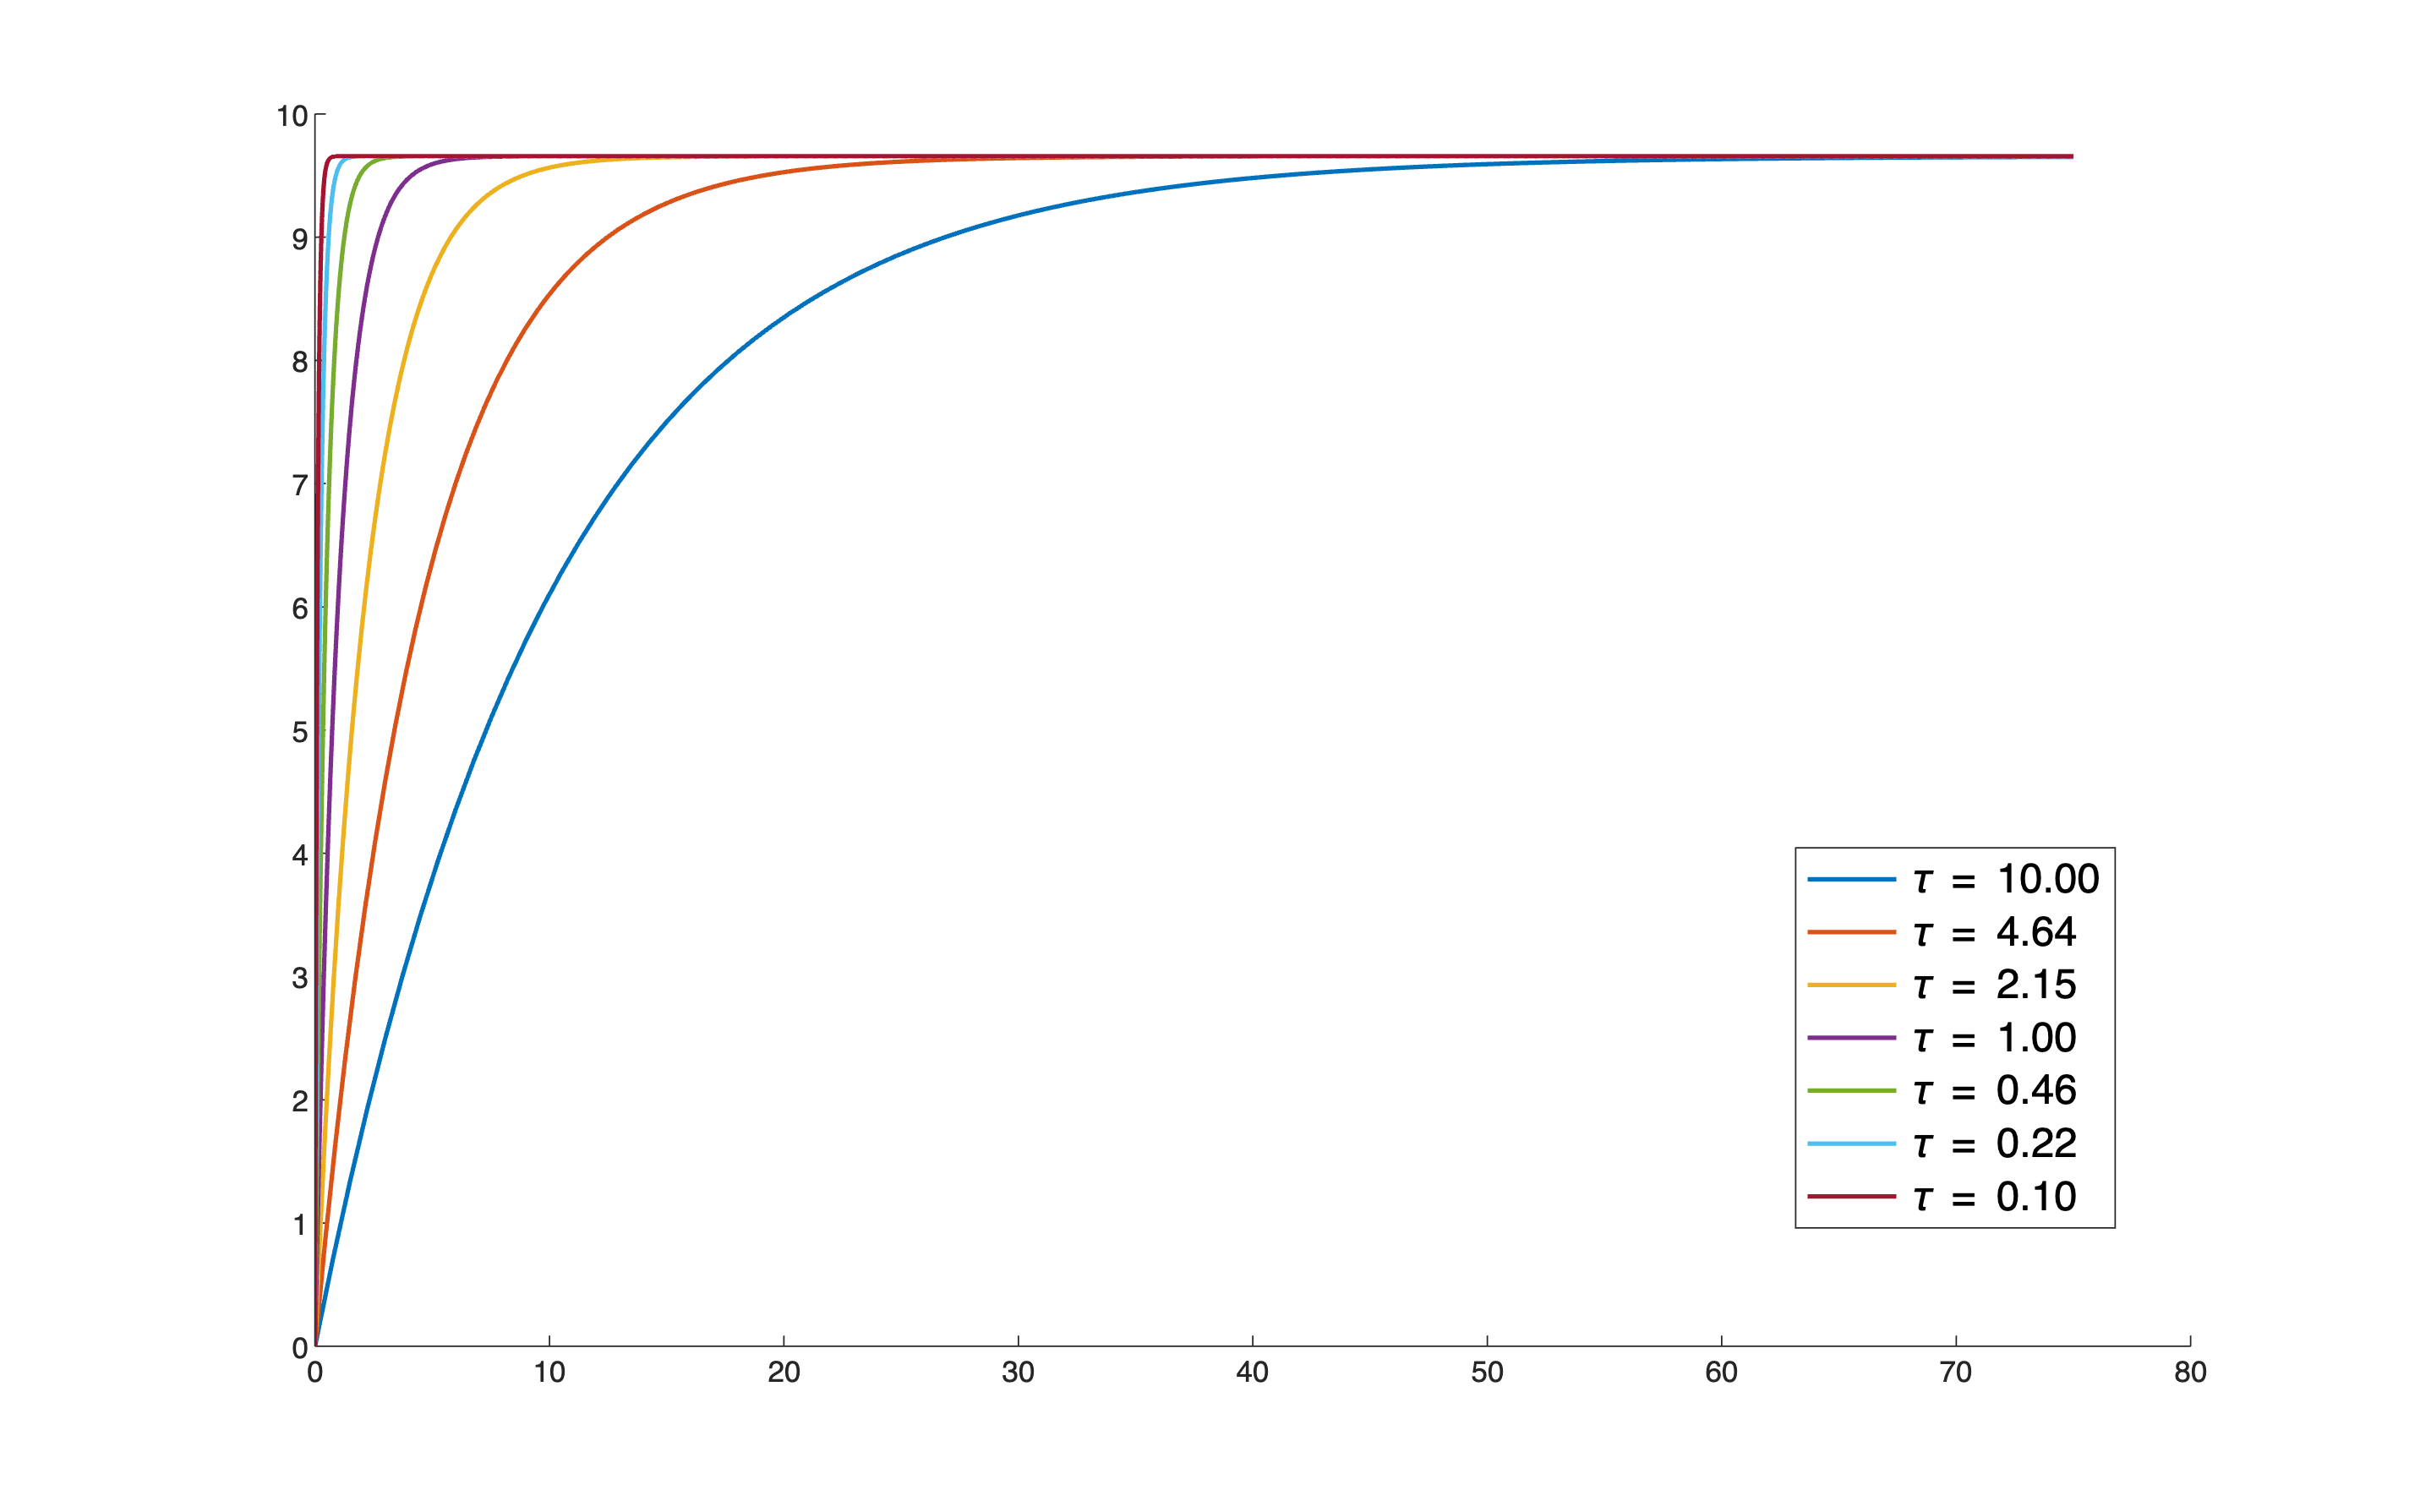

G1sN = struct('tf',cell(1), ...
               'y_step', cell(1), ...
               't_step', cell(1)); % we'll store each different transfer function
G1sStepINFO = cell(Np); % and the step response parameters

figure('Units','normalized', 'Position',[0.1, 0.1,0.99,0.99]);
% let's create a blank figure, as wide as possible
currAx = gca; % retrieve the current axes handler
hold on;

Tfinal = 1.5*5*max(tau_p); % highest than the longest settling time 
for n=Np:-1:1
    % for each pole position
    tau = tau_p(n);
    currGs = tf(muG, [tau +1] ); % 1st order, NO zero
    [Ystep, Tstep] = step(currGs, Tfinal); % plot the current step response
    plot(currAx,Tstep, Ystep, 'LineWidth', 1.5);
    G1sN(n).tf = currGs;
    G1sN(n).y_step = Ystep;
    G1sN(n).t_step = Tstep;
    G1sStepINFO{n} = stepinfo(currGs, "SettlingTimeThreshold", 0.01);
end % for n

formatSpec = '%.2f'; % see 'doc num2str'
legend(['\tau = ', num2str(tau_p(7), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(6), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(5), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(4), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(3), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(2), formatSpec) ], ...
        ['\tau = ', num2str(tau_p(1), formatSpec) ], ...
    'Location', 'best', 'Fontsize', 14)

Notice: the system with $\tau = 10$ has the slowest step response, whereas the system with $\tau = 0.1$ is the fastest one. 

#### The Step Response Characteristic Parameters

Let's analyse the step response parameters, comparing the expressions in Eq. (+) with the estimations obtained by applying the function `stepinfo( )`. 

What does the function `stepinfo( ) `provide`?`

disp(G1sStepINFO{1})

         RiseTime: 0.2197
    TransientTime: 0.4605
     SettlingTime: 0.4605
      SettlingMin: 8.7351
      SettlingMax: 9.6510
        Overshoot: 0
       Undershoot: 0
             Peak: 9.6510
         PeakTime: 0.7322



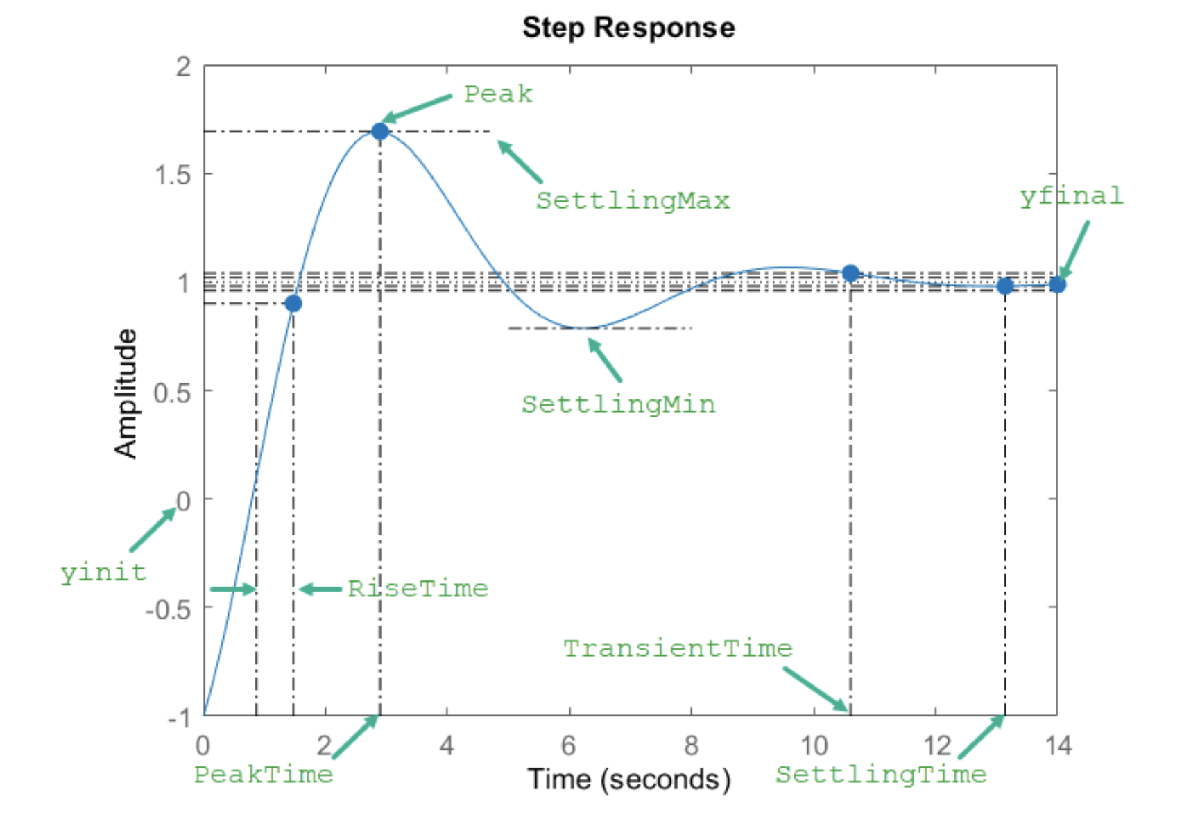

Excerpt from the [MATLAB documentation](https://it.mathworks.com/help/control/ref/dynamicsystem.stepinfo.html?searchHighlight=stepinfo&s_tid=srchtitle_support_results_1_stepinfo).

Let's compare the settling time values, estimates by using Eq. (+) and the `stepinfo( )`:

settlingTformula = zeros(Np,1); % initialise the array used to store
                                % the settling time values  obtained 
                                % using the formula
settlingT_stepinfo = zeros(size(settlingTformula));

for n = 1:Np
    settlingTformula(n) = 4.6 * tau_p(n);
    settlingT_stepinfo(n) = G1sStepINFO{n}.SettlingTime;
end % for n

settlingT_table = table(settlingTformula, settlingT_stepinfo, tau_p', ...
                         'VariableNames',...
                         {'formula 4.6 tau', 'estimated by stepinfo', 'tau values'});

disp(settlingT_table)

    formula 4.6 tau    estimated by stepinfo    tau values
    _______________    _____________________    __________

           0.46               0.46052                0.1  
        0.99104               0.99215            0.21544  
         2.1351                2.1375            0.46416  
            4.6                4.6052                  1  
         9.9104                9.9215             2.1544  
         21.351                21.375             4.6416  
             46                46.052                 10  



As you can note, the values are very close similar for the settling time of each step response.

**Pay attention**: this is the only scenario when both approaches give the same results. Any guess why?

### Not Strictly Proper Systems

Let's consider 


$$G(s) = \mu \frac{1+sT}{1+s \tau} \;,\quad \mu>0\,,\; \tau >0\,,\; T>0$$


Let's choose a fixed pole position in the Left Half Plane of the complex frequency $s$ (LHP for short), a static gain and explore what happens if the zero moves from LHP to RHP (Right Half Plane). 

Do the formulas in Eq. (+) and stepinfo( ) provide similar results this time? 

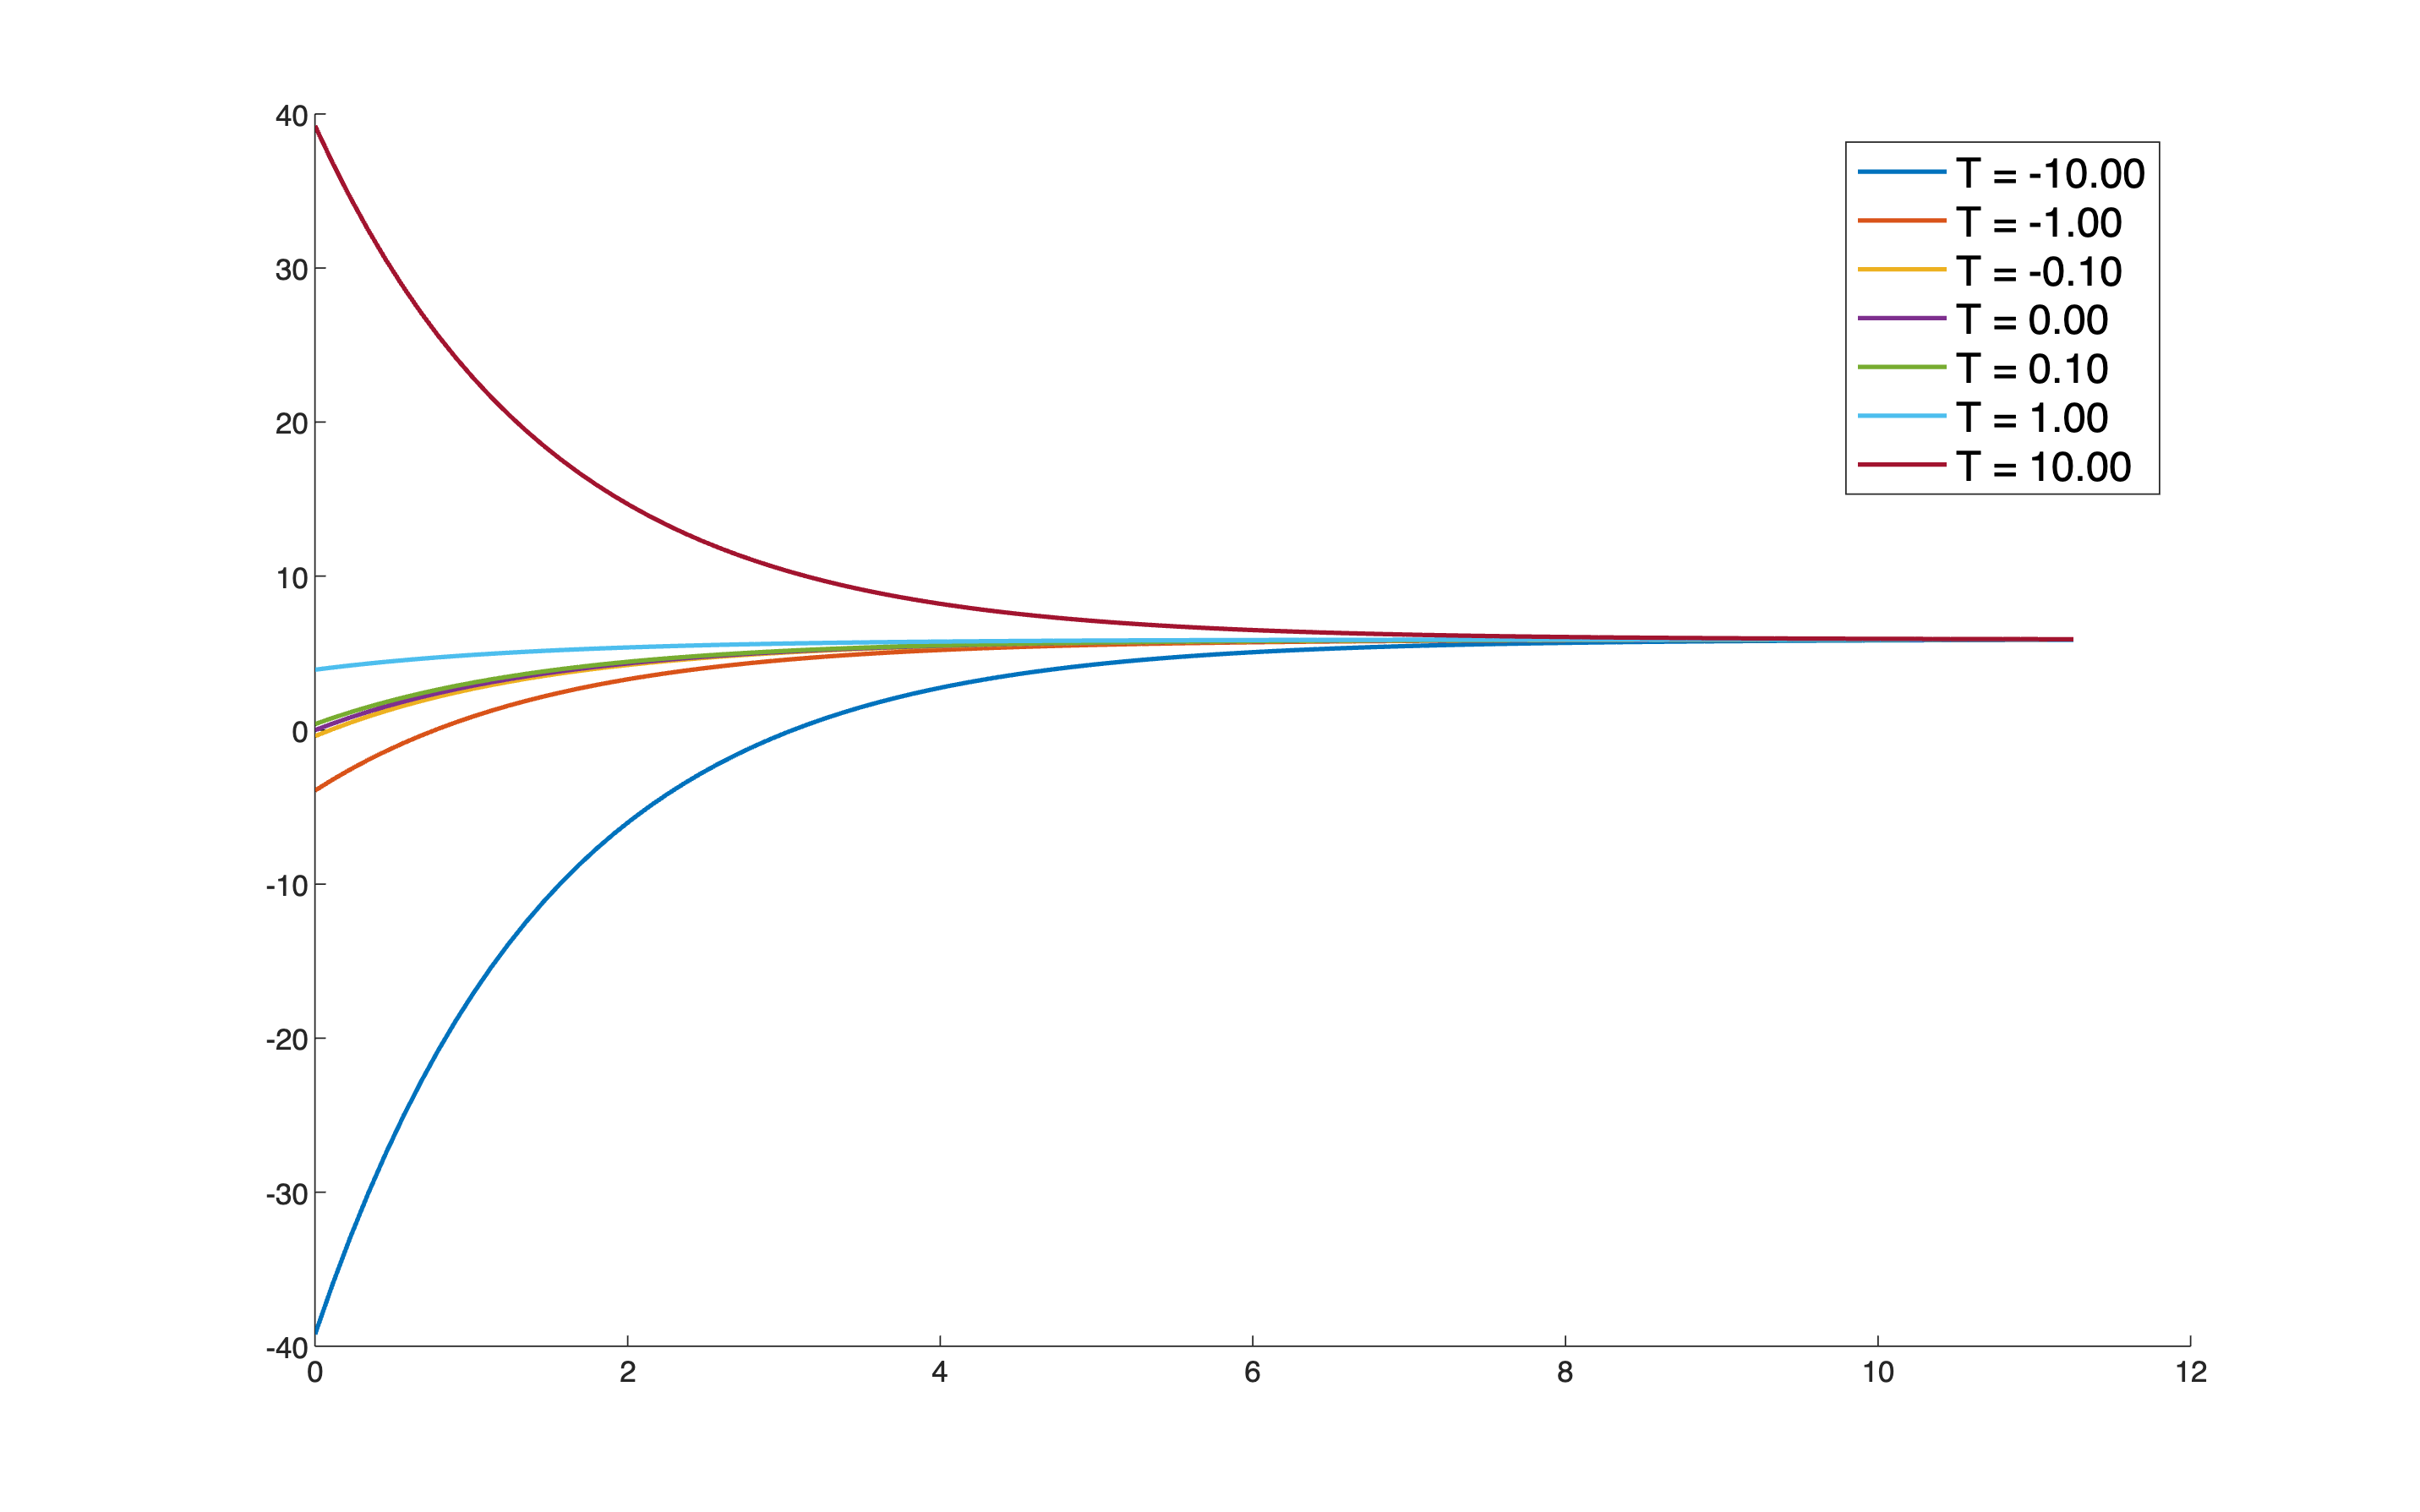

Np = 7; % 7 different pole positions --  we have 7 available colors for plots
T_z = [-fliplr(logspace(-1,1, (floor(Np/2)))), ...
        0, ...
        logspace(-1,1, (floor(Np/2)))]; % Np time constants T, logaritmically spaced,
                            % starting from -1e-1 and ending with -1e+1
tau_p = 1.5;
muG = 2+8*rand(1); % a positive value in the range [2, 10]

G1sZN = struct('tf',cell(1), ...
               'y_step', cell(1), ...
               't_step', cell(1)); % we'll store each different transfer function
G1sZStepINFO = cell(Np); % and the step response parameters

figure('Units','normalized', 'Position',[0.1, 0.1,0.99,0.99]);
% let's create a blank figure, as wide as possible
currAx = gca; % retrieve the current axes handler
hold on;

Tfinal = 1.5*5*max(tau_p); % highest than the longest settling time 
for n=1:Np
    % for each pole position
    Tz = T_z(n);
    currGs = muG* tf([Tz 1], [tau_p +1] ); % 1st order, NO zero
    [Ystep, Tstep] = step(currGs, Tfinal); % plot the current step response
    plot(currAx,Tstep, Ystep, 'LineWidth', 1.5);
    G1sZN(n).tf = currGs;
    G1sZN(n).y_step = Ystep;
    G1sZN(n).t_step = Tstep;
    G1sZStepINFO{n} = stepinfo(currGs, "SettlingTimeThreshold", 0.01);
end % for n

formatSpec = '%.2f'; % see 'doc num2str'
legend(['T = ', num2str(T_z(1), formatSpec) ], ...
        ['T = ', num2str(T_z(2), formatSpec) ], ...
        ['T = ', num2str(T_z(3), formatSpec) ], ...
        ['T = ', num2str(T_z(4), formatSpec) ], ...
        ['T = ', num2str(T_z(5), formatSpec) ], ...
        ['T = ', num2str(T_z(6), formatSpec) ], ...
        ['T = ', num2str(T_z(7), formatSpec) ], ...
    'Location', 'best', 'Fontsize', 14)

#### The Step Response Characteristic Parameters

Let's analyse the step response parameters, comparing the expressions in Eq. (+) with the estimations obtained by applying the function `stepinfo( )`. 

settlingTformula = zeros(Np,1); % initialise the array used to store
                                % the settling time values  obtained 
                                % using the formula
settlingT_stepinfo = zeros(size(settlingTformula));
polePOS = -(1/tau_p)*ones(Np,1);
zeroPOS = zeros(Np,1);

for n = 1:Np
    settlingTformula(n) = 4.6 * tau_p;
    settlingT_stepinfo(n) = G1sZStepINFO{n}.SettlingTime;
    zeroPOS(n) = 1/T_z(n);
end % for n

settlingT_table = table(settlingTformula, settlingT_stepinfo, ...
                          polePOS,  zeroPOS, ... 
                         'VariableNames',...
                         {'formula 4.6 tau', 'estimated by stepinfo', ...
                           'pole p', 'zero z'});

disp(settlingT_table)

    formula 4.6 tau    estimated by stepinfo     pole p     zero z
    _______________    _____________________    ________    ______

          6.9                 9.9634            -0.66667     -0.1 
          6.9                 7.6741            -0.66667       -1 
          6.9                 7.0049            -0.66667      -10 
          6.9                 6.9078            -0.66667      Inf 
          6.9                 6.8047            -0.66667       10 
          6.9                   5.26            -0.66667        1 
          6.9                   9.51            -0.66667      0.1 



## Step Response of Second Order Systems

### Strictly Proper Systems - Complex Poles, no Zeros

Let's consider 


$$G(s) = \frac{\mu}{1+\frac{2\xi}{\omega_n}s +\frac{1}{\omega_n^2} s^2} \;,\quad \mu>0\,,\; \omega_n >0\,,\; 0 \le \xi \le1$$


 
$$t_s \approx \frac{4.6}{\xi \omega_n} \quad (\star)$$


Let's choose a constant value for $\omega_n$ and $\mu$,  and explore what happens if the damping factor $\xi$ moves from $0$ to $1$.  Let's analyse the step response parameters, comparing the expressions in Eq. ( $\star$ ) with the estimations obtained by applying the function `stepinfo( )`. 

Np = 7; % 7 different pole positions --  we have 7 available colors for plots
xi_val = linspace(1e-1,1-1e-1,7); % Np damping factor values

omega_n_p = 4.5;
muG = 2+8*rand(1); % a positive value in the range [2, 10]

G2sN = struct('tf',cell(1), ...
               'y_step', cell(1), ...
               't_step', cell(1)); % we'll store each different transfer function
G2sStepINFO = cell(Np,1); % and the step response parameters

Tfinal = 1.5*5*(1/omega_n_p/1e-1); % highest than the longest settling time 

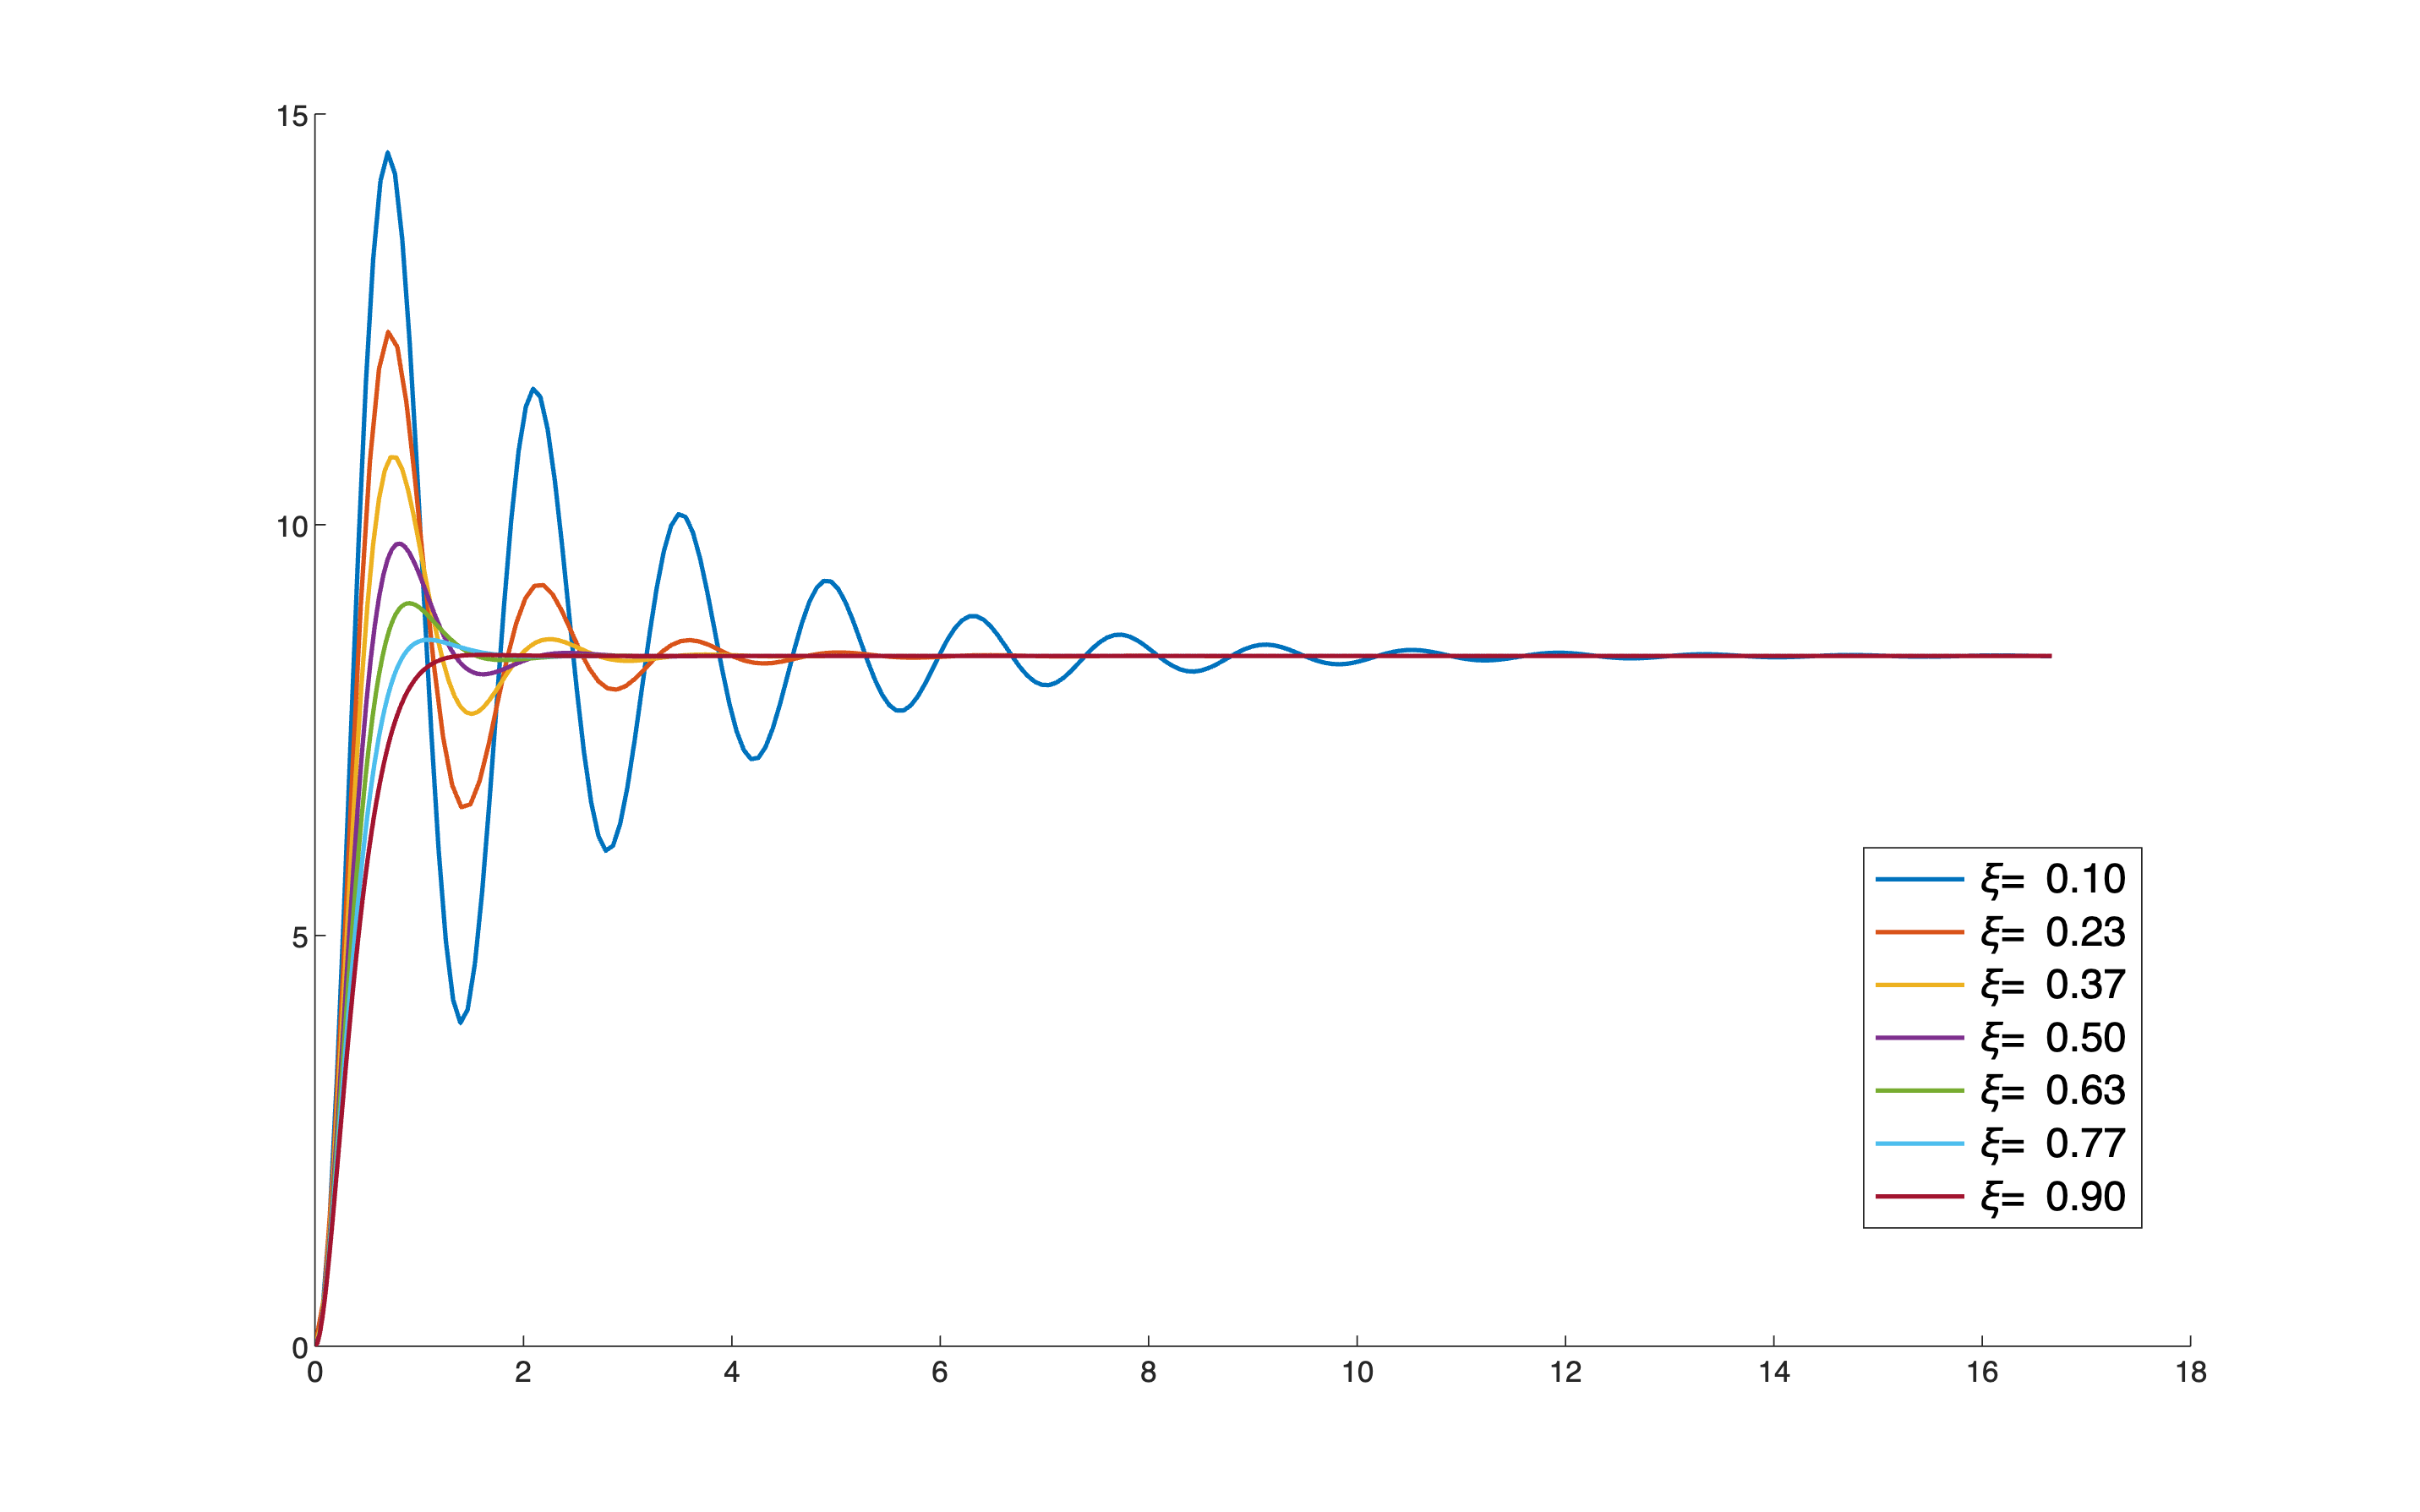

figure('Units','normalized', 'Position',[0.1, 0.1,0.99,0.99]);
% let's create a blank figure, as wide as possible
currAx = gca; % retrieve the current axes handler
hold on;

for n=1:Np
    % for each pole position
    currXi = xi_val(n);
    currGs =  tf(muG, [(1/omega_n_p.^2) (2*currXi/omega_n_p) +1] ); % 2nd order, NO zero
    [Ystep, Tstep] = step(currGs, Tfinal); % plot the current step response
    plot(currAx,Tstep, Ystep, 'LineWidth', 1.5);
    G2sN(n).tf = currGs;
    G2sN(n).y_step = Ystep;
    G2sN(n).t_step = Tstep;
    G2sStepINFO{n} = stepinfo(currGs, "SettlingTimeThreshold", 0.01);
end % for n
legend(['\xi= ',num2str(xi_val(1), formatSpec) ], ...
         ['\xi= ', num2str(xi_val(2), formatSpec) ], ...
         ['\xi= ',num2str(xi_val(3), formatSpec) ], ...
         ['\xi= ',num2str(xi_val(4), formatSpec) ], ...
         ['\xi= ',num2str(xi_val(5), formatSpec) ], ...
         ['\xi= ',num2str(xi_val(6), formatSpec) ], ...
         ['\xi= ',num2str(xi_val(7), formatSpec) ],...
             'Location', 'best', 'Fontsize', 14)

#### The Step Response Characteristic Parameters

Let's analyse the step response parameters, comparing the expressions in Eq. (+) with the estimations obtained by applying the function `stepinfo( )`. 

settlingTformula = zeros(Np,1); % initialise the array used to store
                                % the settling time values  obtained 
                                % using the formula
settlingT_stepinfo = zeros(size(settlingTformula));

for n = 1:Np
    settlingTformula(n) = 4.6 /(omega_n_p*xi_val(n));
    settlingT_stepinfo(n) = G2sStepINFO{n}.SettlingTime;
end % for n

settlingT_table = table(settlingTformula, settlingT_stepinfo, xi_val', ...
                         'VariableNames',...
                         {'formula 4.6/(omega_n * xi)', 'estimated by stepinfo', 'damping factor'});

disp(settlingT_table)

    formula 4.6/(omega_n * xi)    estimated by stepinfo    damping factor
    __________________________    _____________________    ______________

              10.222                     9.9529                   0.1    
               4.381                     4.3977               0.23333    
              2.7879                     2.5537               0.36667    
              2.0444                     1.9513                   0.5    
               1.614                     1.4189               0.63333    
              1.3333                     1.4577               0.76667    
              1.1358                     1.1395                   0.9    



### Not Strictly Proper Systems - Complex Poles, one Zeros

Let's consider 


$$G(s) = \frac{\mu (1+sT)}{1+\frac{2\xi}{\omega_n}s +\frac{1}{\omega_n^2} s^2} \;,\quad \mu>0\,,\; \omega_n >0\,,\; T>0,\; 0 \le \xi \le1$$


 
$$t_s \approx \frac{4.6}{\xi \omega_n} \quad (\star)$$


Let's choose a constant value for $\omega_n$, $T$ and $\mu$,  and explore what happens if the damping factor $\xi$ moves from $0$ to $1$.  Let's analyse the step response parameters, comparing the expressions in Eq. ( $\star$ ) with the estimations obtained by applying the function `stepinfo( )`. 

Np = 7; % 7 different pole positions --  we have 7 available colors for plots
xi_val = linspace(1e-1,1-1e-1,7); % Np damping factor values

omega_n_p = 4.5;
muG = 2+8*rand(1); % a positive value in the range [2, 10]
T = 1.25;

G2sN = struct('tf',cell(1), ...
               'y_step', cell(1), ...
               't_step', cell(1)); % we'll store each different transfer function
G2sStepINFO = cell(Np,1); % and the step response parameters

Tfinal = 1.5*5*(1/omega_n_p/1e-1); % highest than the longest settling time 

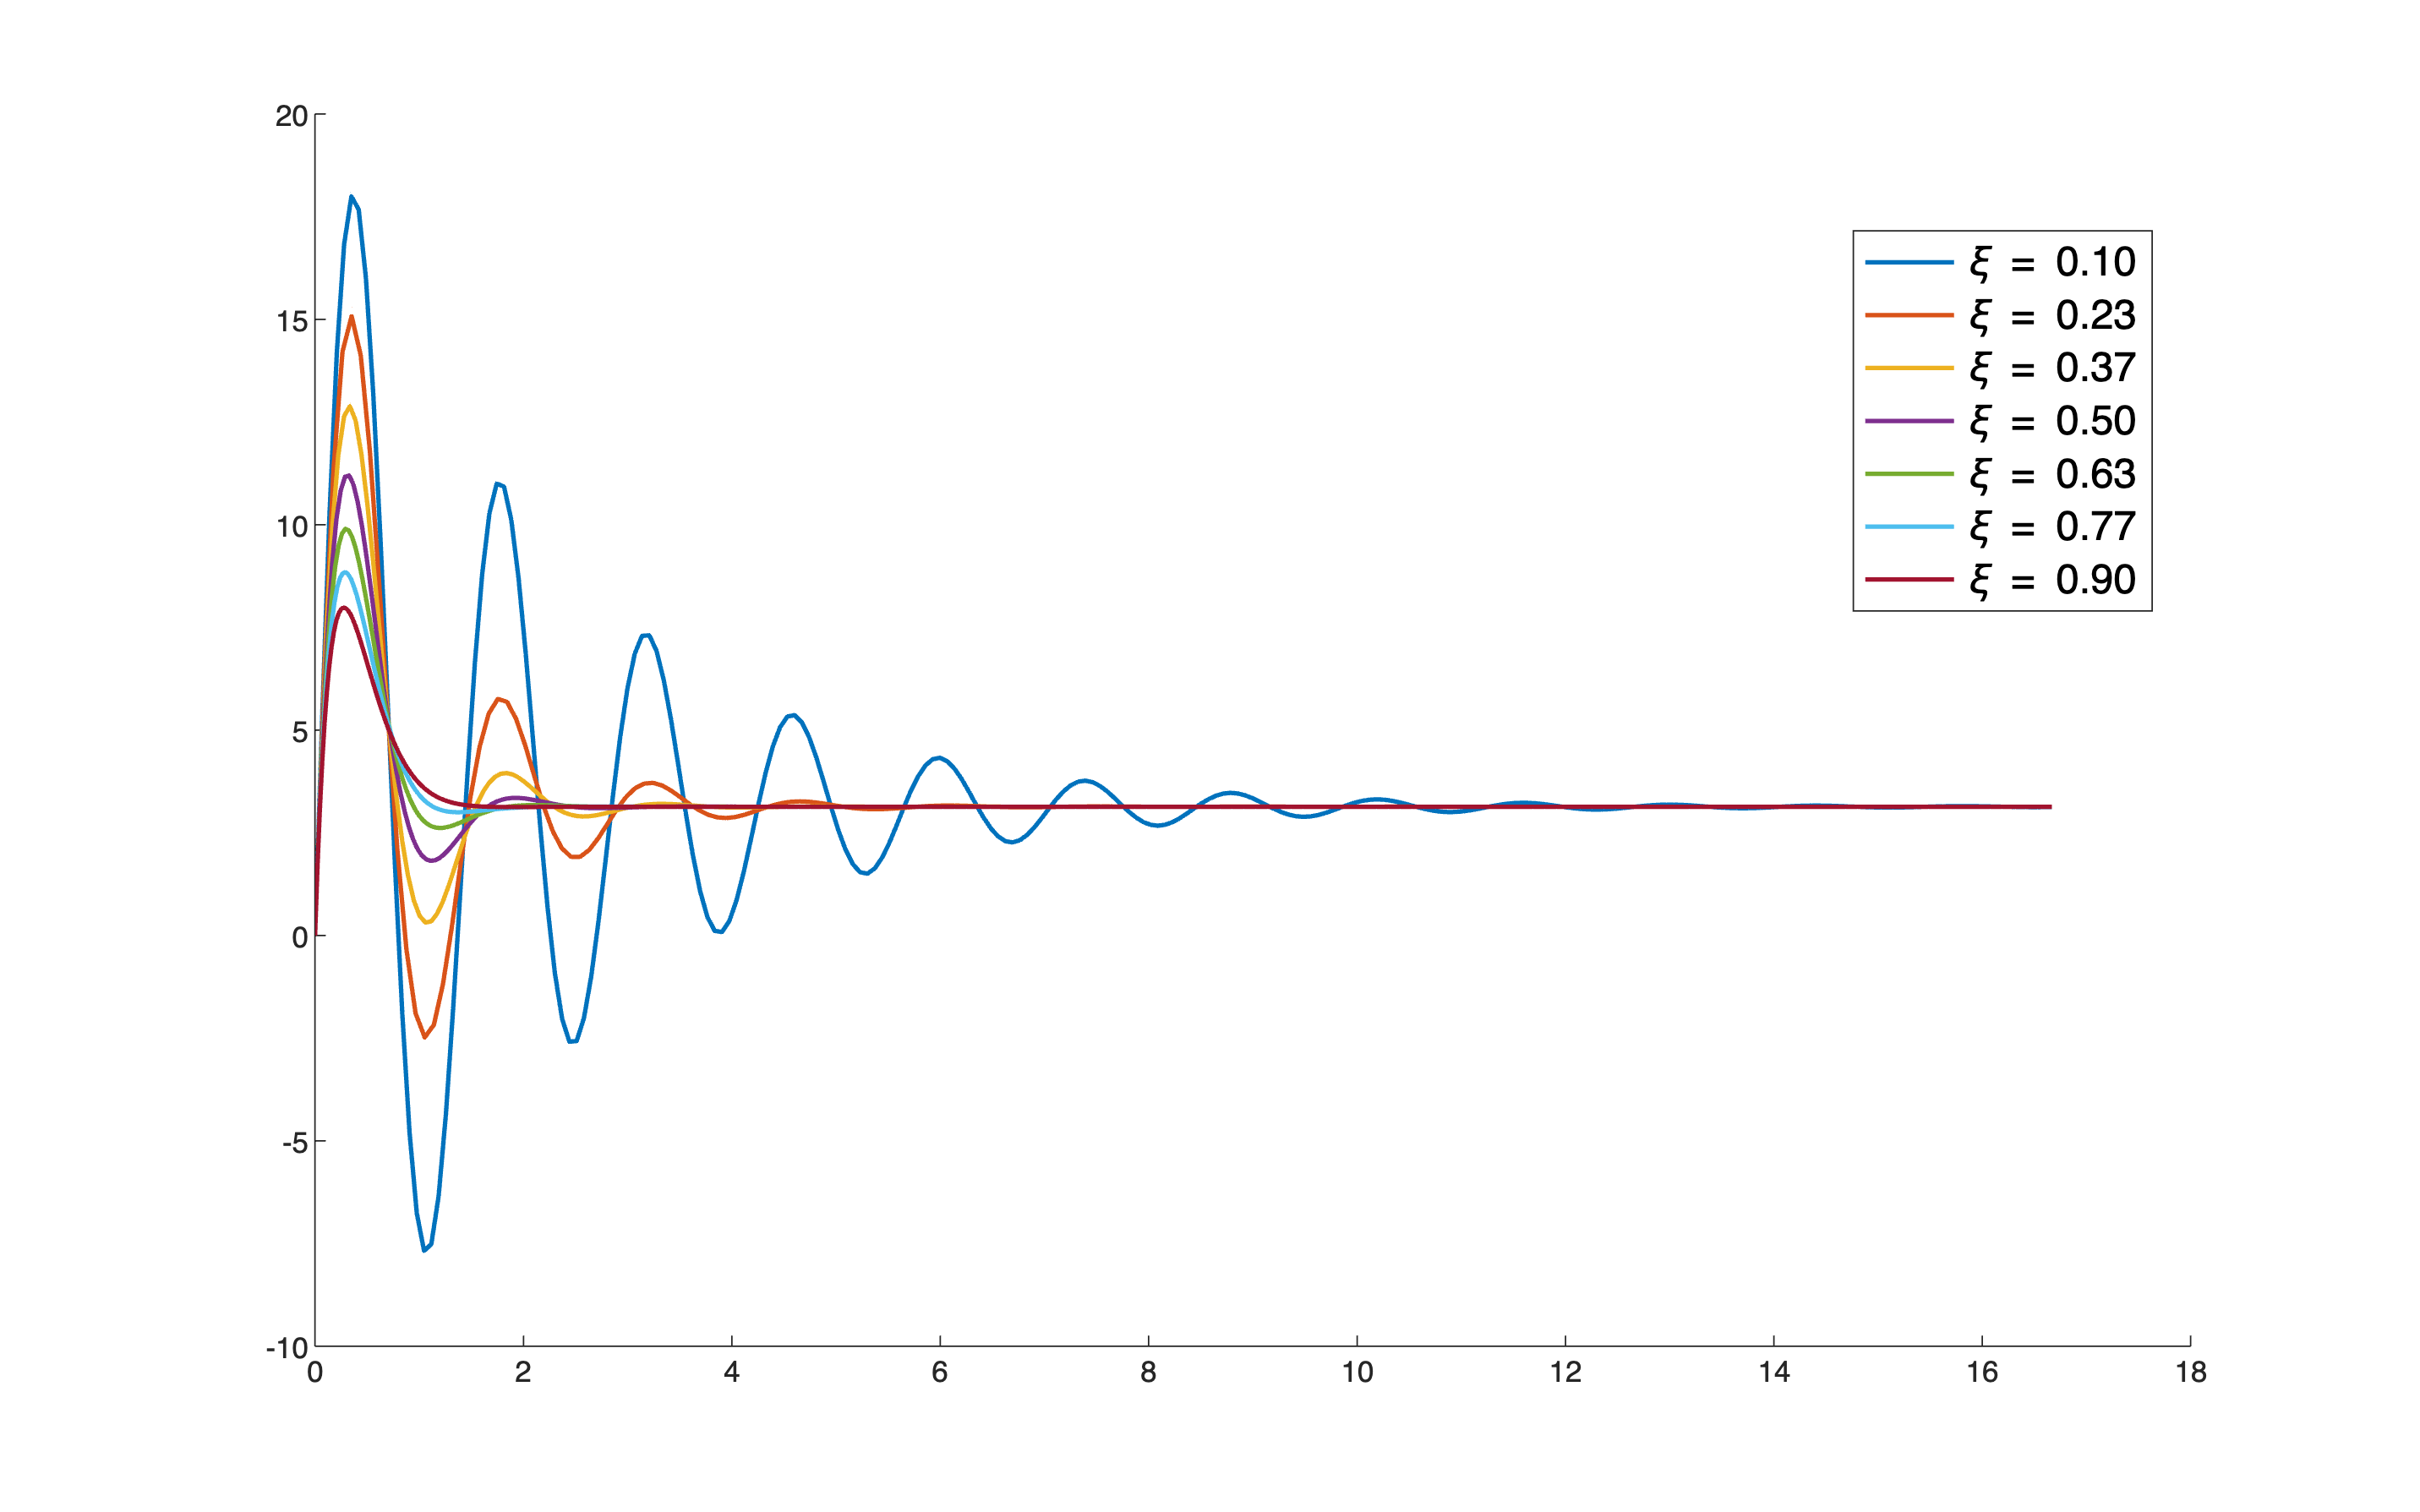

figure('Units','normalized', 'Position',[0.1, 0.1,0.99,0.99]);
% let's create a blank figure, as wide as possible
currAx = gca; % retrieve the current axes handler
hold on;

for n=1:Np
    % for each pole position
    currXi = xi_val(n);
    currGs =  muG*tf([T 1], [(1/omega_n_p.^2) (2*currXi/omega_n_p) +1] ); % 2nd order, NO zero
    [Ystep, Tstep] = step(currGs, Tfinal); % plot the current step response
    plot(currAx,Tstep, Ystep, 'LineWidth', 1.5);
    G2sN(n).tf = currGs;
    G2sN(n).y_step = Ystep;
    G2sN(n).t_step = Tstep;
    G2sStepINFO{n} = stepinfo(currGs, "SettlingTimeThreshold", 0.01);
end % for n
formatSpec = '%.2f'; % see 'doc num2str'
legend(['\xi = ',num2str(xi_val(1), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(2), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(3), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(4), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(5), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(6), formatSpec) ], ...
         ['\xi = ',num2str(xi_val(7), formatSpec) ],...
             'Location', 'best', 'Fontsize', 14)

#### The Step Response Characteristic Parameters

Let's analyse the step response parameters, comparing the expressions in Eq. (+) with the estimations obtained by applying the function `stepinfo( )`. 

settlingTformula = zeros(Np,1); % initialise the array used to store
                                % the settling time values  obtained 
                                % using the formula
settlingT_stepinfo = zeros(size(settlingTformula));

for n = 1:Np
    settlingTformula(n) = 4.6 /(omega_n_p*xi_val(n));
    settlingT_stepinfo(n) = G2sStepINFO{n}.SettlingTime;
end % for n

settlingT_table = table(settlingTformula, settlingT_stepinfo, xi_val', ...
                         'VariableNames',...
                         {'formula 4.6/(omega_n * xi)', 'estimated by stepinfo', 'damping factor'});



disp(settlingT_table)

    formula 4.6/(omega_n * xi)    estimated by stepinfo    damping factor
    __________________________    _____________________    ______________

              10.222                     13.826                   0.1    
               4.381                     5.6224               0.23333    
              2.7879                     3.6155               0.36667    
              2.0444                     2.8412                   0.5    
               1.614                     2.2725               0.63333    
              1.3333                      1.874               0.76667    
              1.1358                     1.4667                   0.9    



## Systems of Order greater than 2 - Dominant Poles Approximation

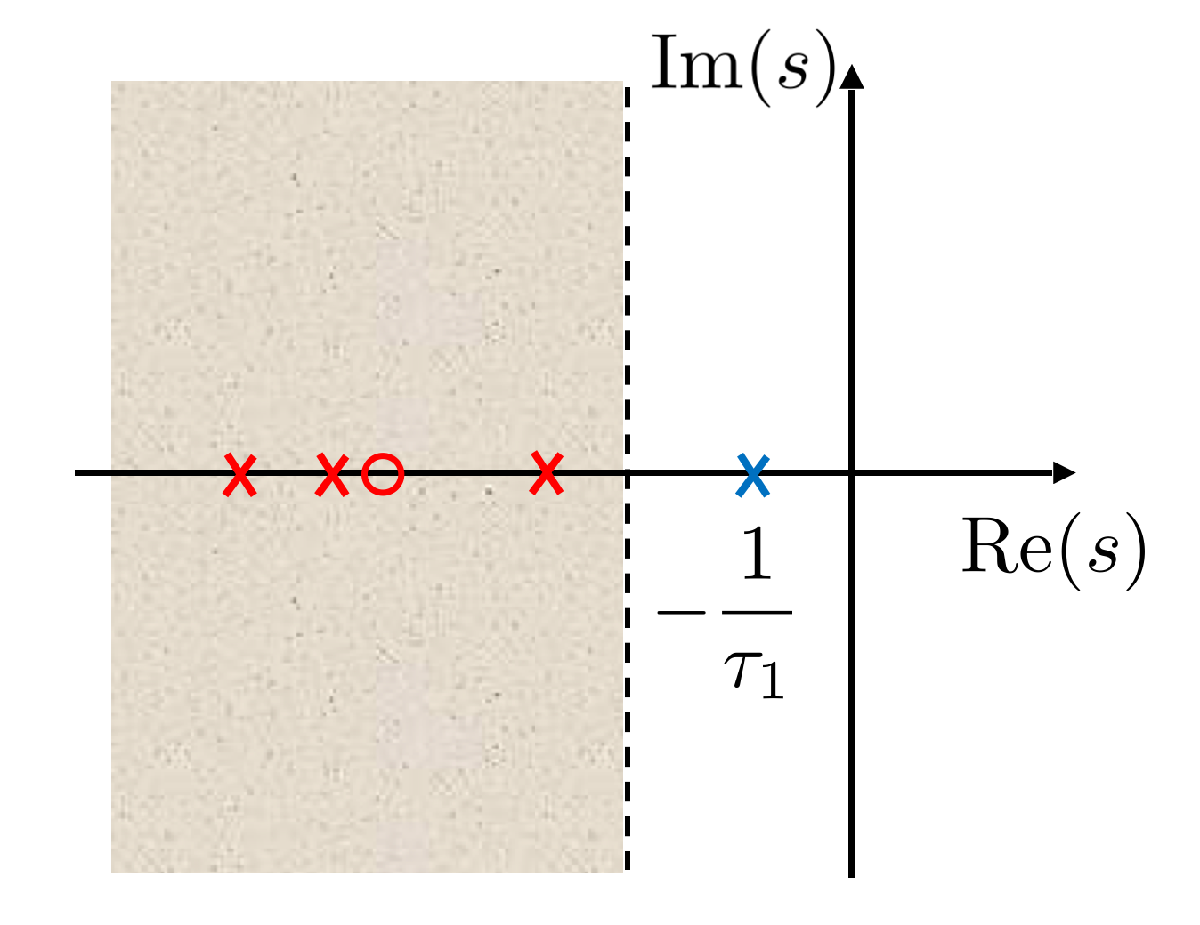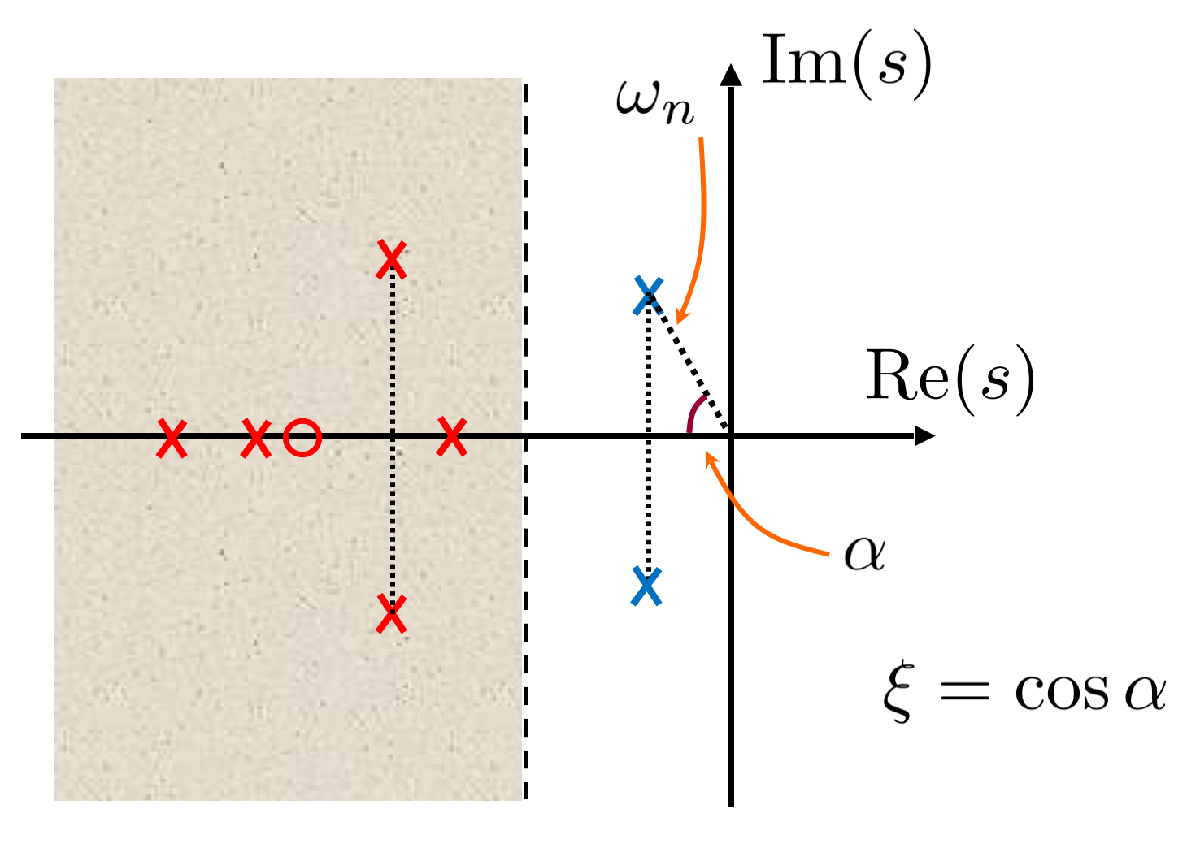

When using the dominant poles approximation:

- It is essential to “preserve” the gain

- Zeros located close to the imaginary axis have to be adequately taken into account

This approximation is valid in qualitative analysis and for the initial and rough controller’s design steps. Refer to Part 7 of the course material.

### Example - A Real Dominant Pole

Consider the LTI system described by the transfer function


$$G_1(s) = \frac{250\,\left(1+\frac{s}{10} \right)}{\Big(1+20\,s\Big)\left(1+\frac{s}{5} \right) \left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


clear
s = tf('s'); % the transfer function building helper

G1s = 250*(1+s/10)/( (1+20*s)*(1+s/5)*(1+(9/20)*s+s^2/16) ); % the tranfer function

set(G1s,"Name", "G1");
G1_staticGAIN = dcgain(G1s) % the static gain of the LTI system

G1_staticGAIN = 250


p_G1s = sort(pole(G1s), 'ascend') % the poles of the transfer function

p_G1s =   -0.0500 + 0.0000i
  -3.6000 - 1.7436i
  -3.6000 + 1.7436i
  -5.0000 + 0.0000i



zero(G1s) % the zeros of the transfer function

ans = -10

The poles and zeros configuration of the system is as follows

hf = figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
hPZP = pzplot(hf, G1s);
grid on
get(hPZP)

             AxesStyle: [1×1 controllib.chart.internal.options.AxesStyle]
       Characteristics: []
         FrequencyUnit: "rad/s"
      HandleVisibility: 'on'
         InnerPosition: [0.0543 0.0868 0.8915 0.8382]
                Layout: [0×0 matlab.ui.layout.LayoutOptions]
            LegendAxes: [1 1]
        LegendAxesMode: "auto"
        LegendLocation: "northeast"
     LegendOrientation: "vertical"
         LegendVisible: off
              NextPlot: "replace"
         OuterPosition: [0 0 1 1]
                Parent: [1×1 Figure]
              Position: [0.0543 0.0868 0.8915 0.8382]
    PositionConstraint: 'outerposition'
             Responses: [1×1 controllib.chart.response.PZResponse]
              Subtitle: [1×1 controllib.chart.internal.options.AxesLabel]
              TimeUnit: "seconds"
                 Title: [1×1 controllib.chart.internal.options.AxesLabel]
                 Units: 'normalized'
               Visible: on
                XLabel: [1×1 controllib.chart.inter

get(hPZP.Responses(1))

       SourceData: [1×1 struct]
             Name: "G1"
          Visible: on
    LegendDisplay: on
       MarkerSize: 6
        LineWidth: 0.5000
            Color: [0 0.4470 0.7410]



% PZPlot properties:
% https://it.mathworks.com/help/ident/ref/controllib.chart.pzplot-properties.html
% https://it.mathworks.com/matlabcentral/answers/2173352-change-marker-colour-of-pzplot
%
hPZP.Responses(1).MarkerSize = 12;
hPZP.Responses(1).LineWidth = 2;
hPZP.Responses(1).Color = 'r';
get(hPZP.AxesStyle(1))

              Box: on
         FontSize: 10
       FontWeight: "normal"
        FontAngle: "normal"
         FontName: "Helvetica"
       RulerColor: [0.3804 0.3804 0.3804]
      GridVisible: on
        GridColor: [0.1294 0.1294 0.1294]
    GridLineWidth: 0.5000




% see 'doc pzplot' & 'doc pzoptions'
hPZP.AxesStyle(1).FontSize = 14;
hPZP.AxesStyle(1).GridColor = [0,0,0];

hPZP.XLabel(1)

ans =   AxesLabel with properties:

         String: "Real Axis"
       FontSize: 11
     FontWeight: "normal"
      FontAngle: "normal"
       FontName: "Helvetica"
          Color: [0.1294 0.1294 0.1294]
    Interpreter: "tex"
       Rotation: 0
        Visible: on


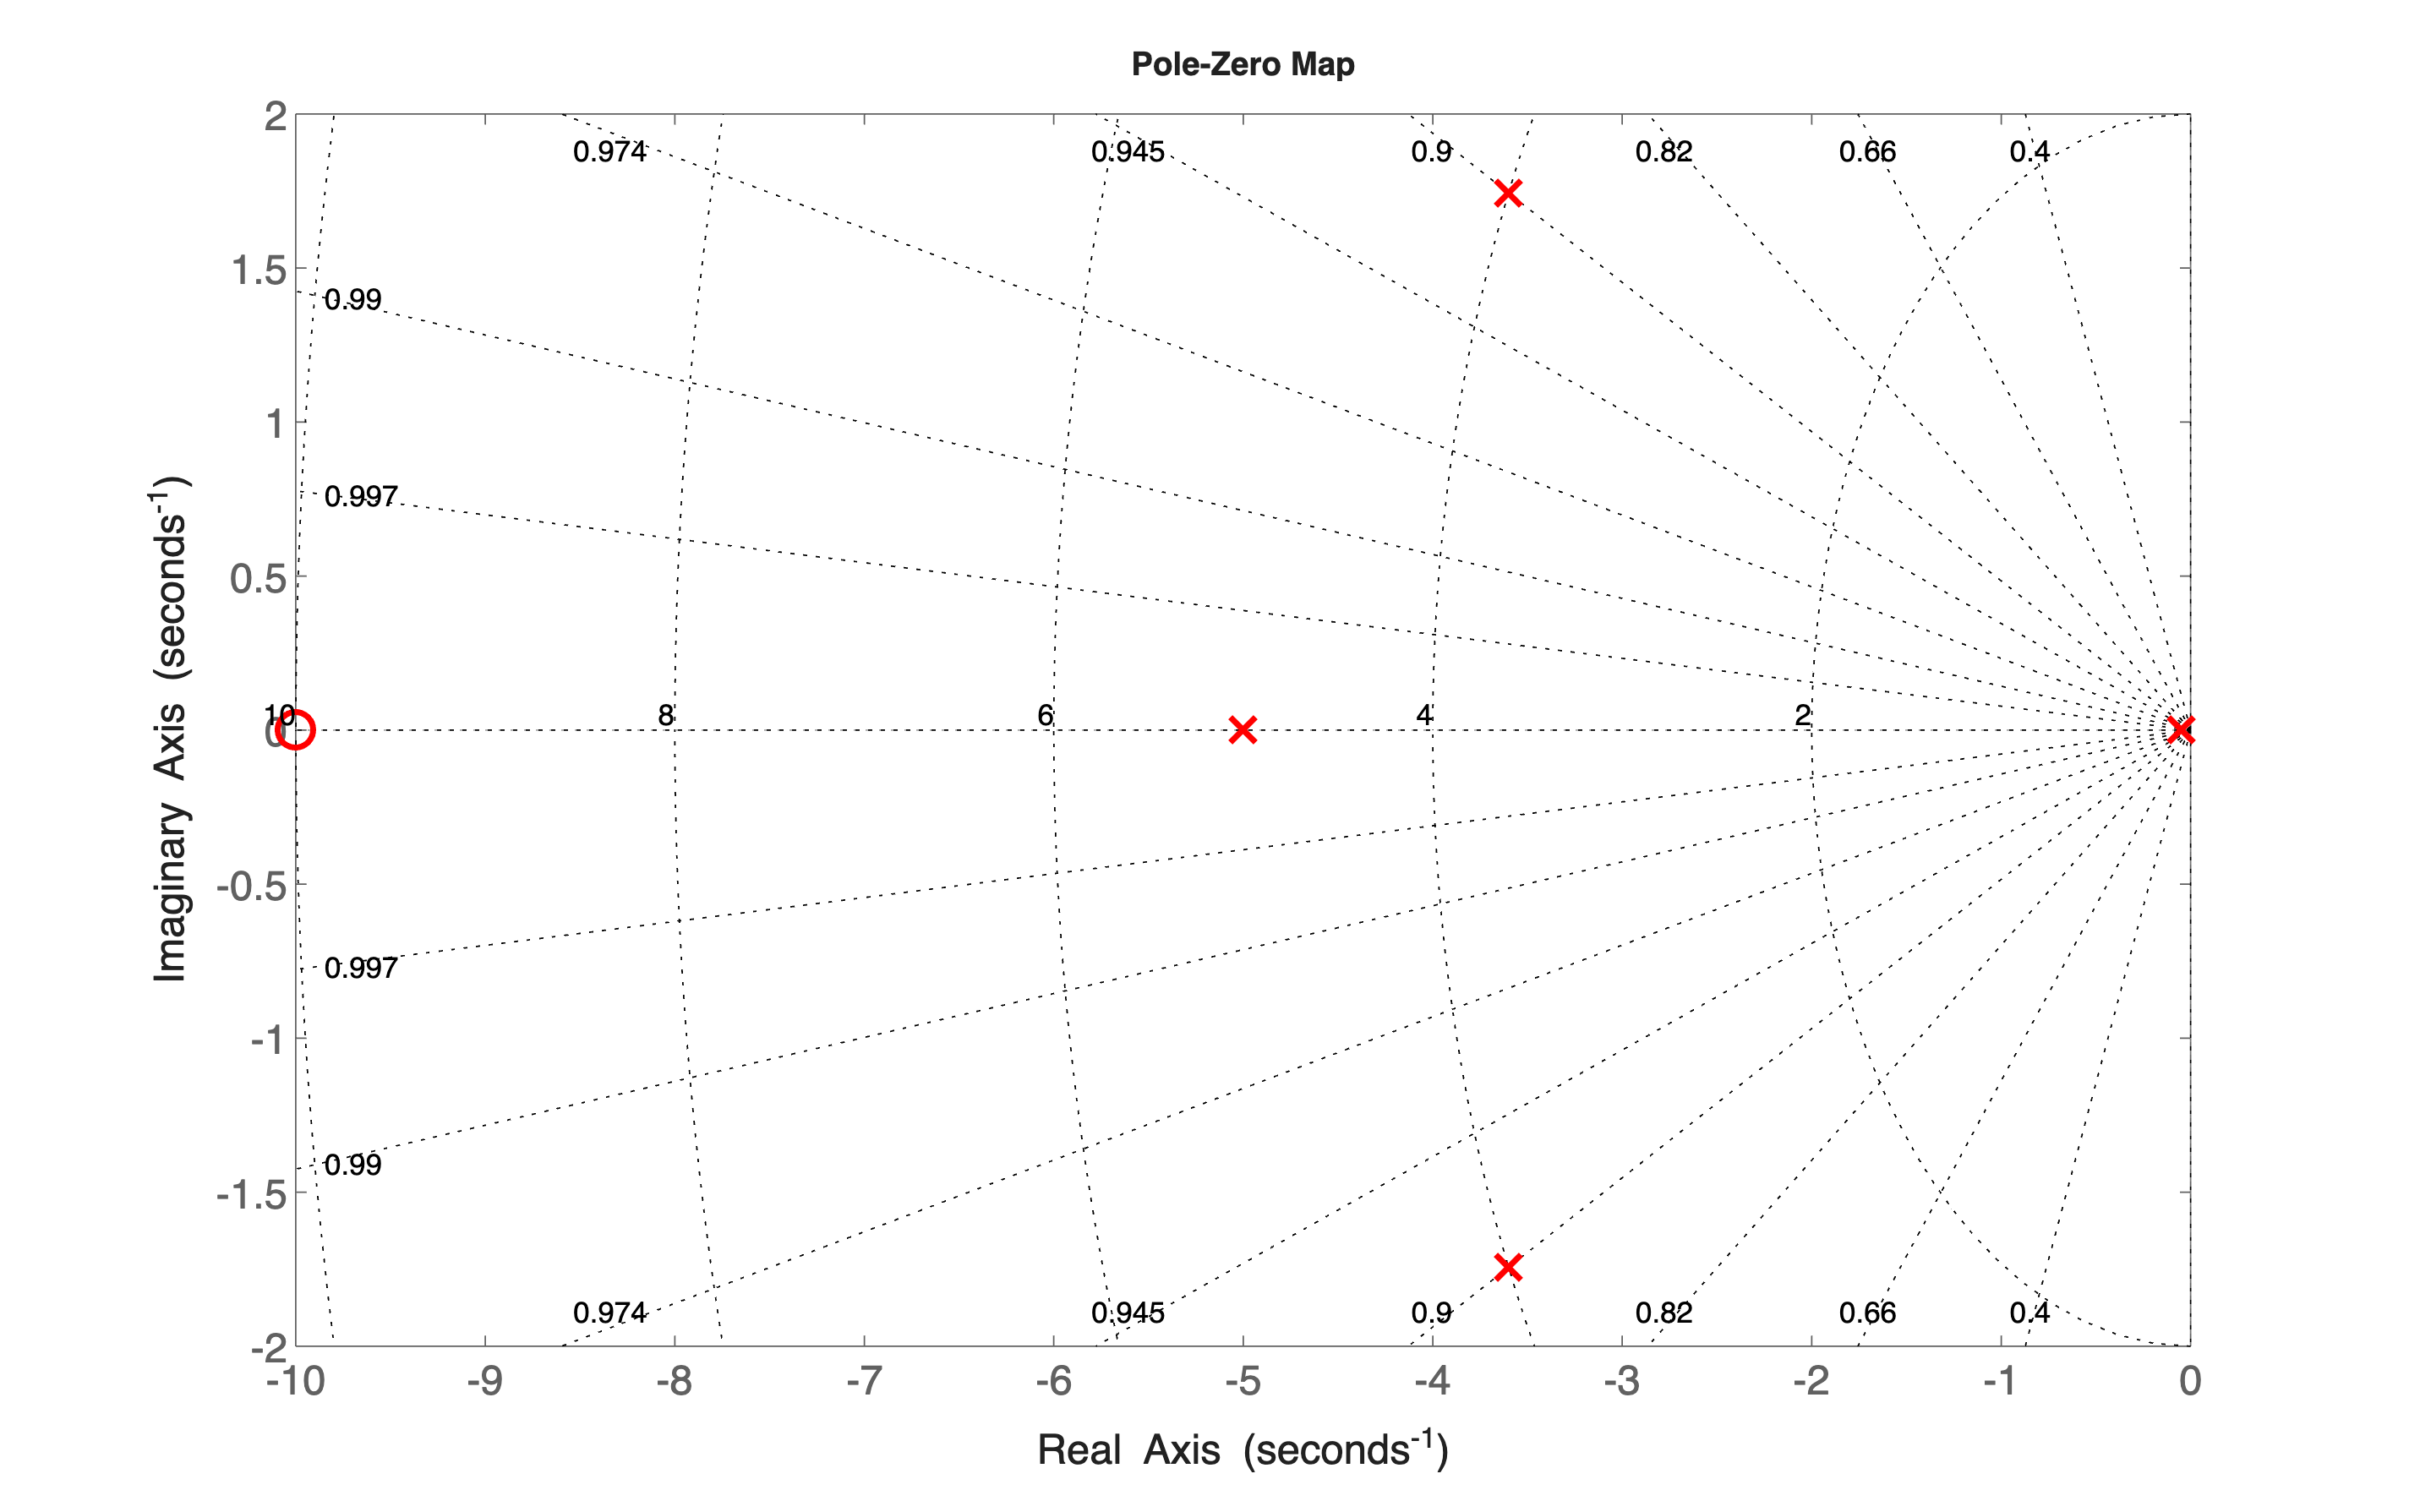

hPZP.XLabel(1).FontSize = 14;
hPZP.YLabel(1).FontSize = 14;

The pole closest to the origin is the dominant one.

#### The Dominant Pole Approximation

We may approximate the system $G_1(s)$ using a very simple model: the static gain and the real dominant pole:


$$G_{1\,\text{app}}(s) = 250 \cdot \frac{1}{\left(1+ 20\,s \right)$$


tau1 = abs(1/p_G1s(1))

tau1 = 20

G1sApprox = tf([G1_staticGAIN], [tau1 1], "Name", "G_approx")


G1sApprox =
 
    250
  --------
  20 s + 1
 
Name: G_approx
Continuous-time transfer function.
Model Properties


Let's compare the step response of system $G_1(s)$ with the approximate model:

hf = figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
% let's create a blank figure

rpSP = stepplot(G1s, G1sApprox, [0, 180]);
rpSP

rpSP =   StepPlot with properties:

          Responses: [2×1 controllib.chart.response.StepResponse]
    Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

           TimeUnit: "seconds"
          Normalize: off

            Visible: on
         IOGrouping: "none"
       InputVisible: on
      OutputVisible: on

  Show all properties



% refer to https://it.mathworks.com/help/control/ug/customizing-response-plots-from-the-command-line.html
rpSP.Characteristics(1).SettlingTime(1).Threshold = 0.01; % 1 %
rpSP.Characteristics(1).SettlingTime(1).Visible = "on"; 
rpSP.Characteristics(1).SteadyState(1).Visible = "on";
rpSP.LegendVisible = "on";
rpSP.LegendLocation = "best";

grid on; 
rpSP.Responses

ans =   2×1 StepResponse array:

  StepResponse    (G1)
  StepResponse    (G_approx)


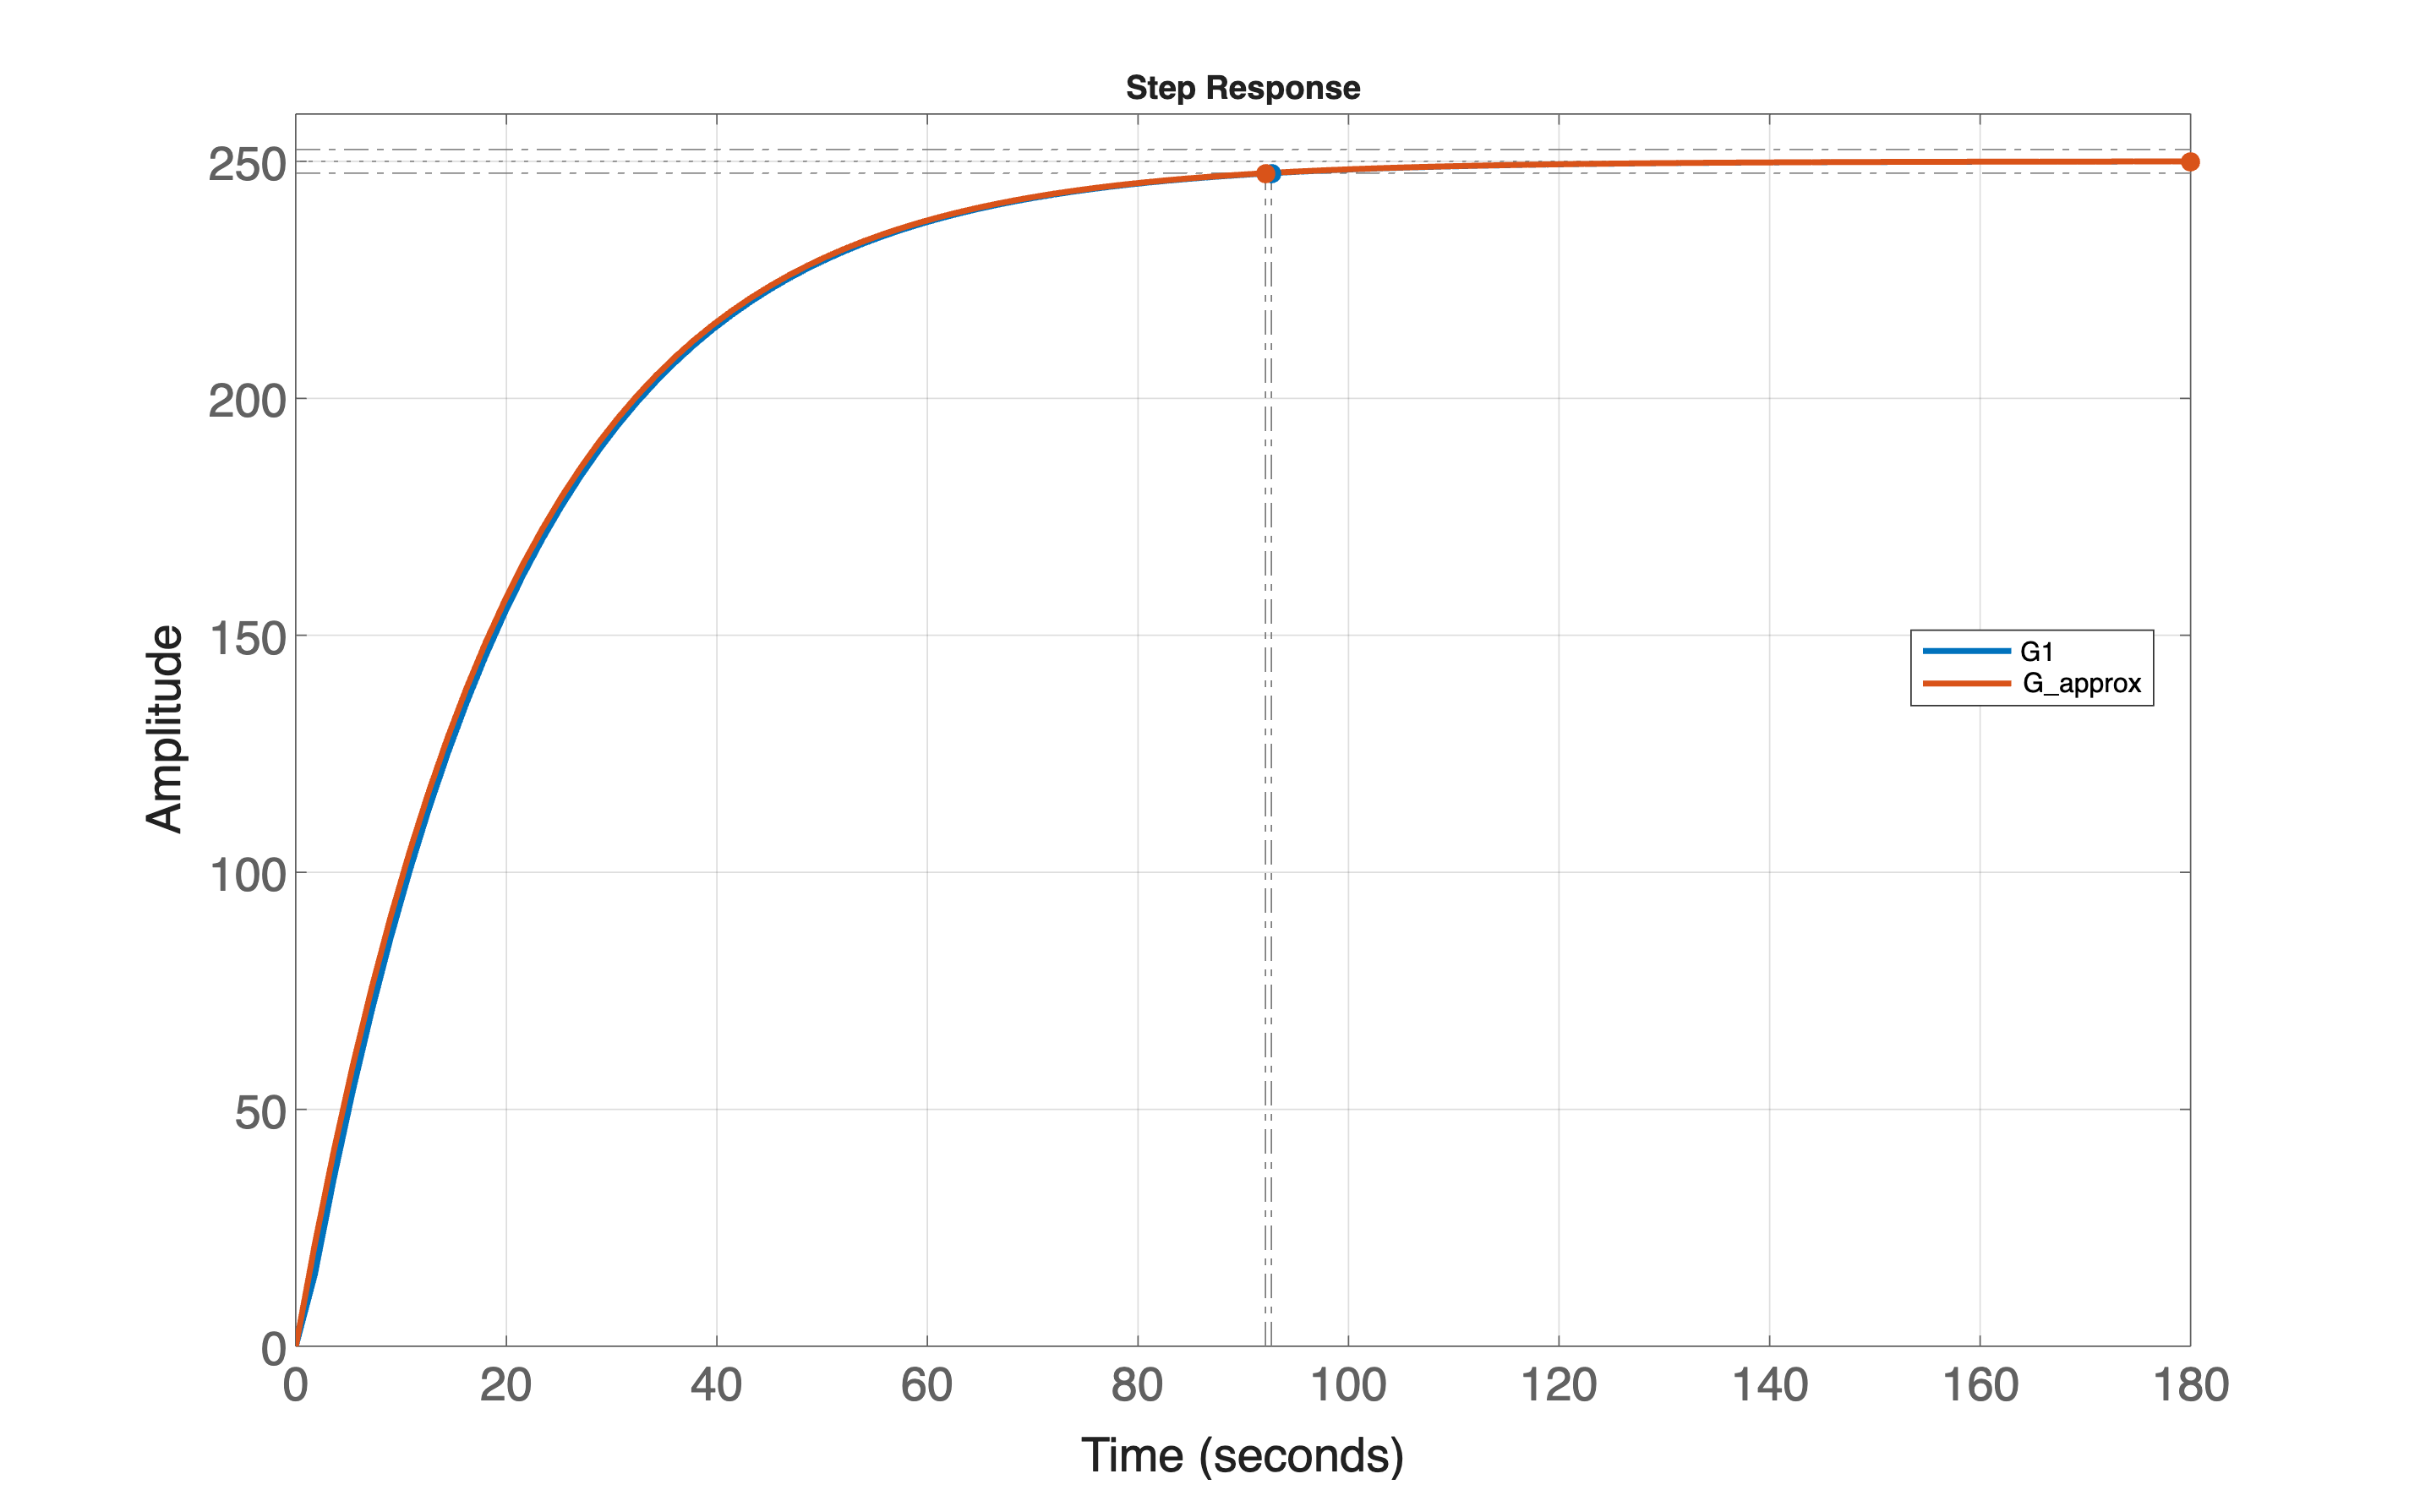


rpSP.Responses(1).LineWidth = 2;
rpSP.Responses(2).LineWidth = 2;
ylim([0, 260]);
rpSP.AxesStyle(1).FontSize=16;
rpSP.XLabel(1).FontSize = 16;
rpSP.YLabel(1).FontSize = 16;



G1info = stepinfo(G1s, "SettlingTimeThreshold", 0.01)

G1info = struct with fields:
         RiseTime: 43.9474
    TransientTime: 92.6612
     SettlingTime: 92.6612
      SettlingMin: 225.4562
      SettlingMax: 249.8302
        Overshoot: 0
       Undershoot: 0
             Peak: 249.8302
         PeakTime: 146.4444



G1APPROXinfo = stepinfo(G1sApprox, "SettlingTimeThreshold", 0.01)

G1APPROXinfo = struct with fields:
         RiseTime: 43.9401
    TransientTime: 92.1034
     SettlingTime: 92.1034
      SettlingMin: 226.1252
      SettlingMax: 249.8348
        Overshoot: 0
       Undershoot: 0
             Peak: 249.8348
         PeakTime: 146.4444


### Example 2 - A Real Dominant Pole and a Zero close to the Origin

Consider the LTI system described by the transfer function


$$G_2(s) = \frac{250\,\left(1+50\,s \right)}{\Big(1+20\,s\Big)\left(1+\frac{s}{5} \right) \left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


clear
s = tf('s'); % the transfer function building helper

G2s = 250*(1+50*s)/( (1+20*s)*(1+s/5)*(1+(9/20)*s+s^2/16) ); % the tranfer function
set(G2s,"Name", "G2");

G2_staticGAIN = dcgain(G2s) % the static gain of the LTI system

G2_staticGAIN = 250


p_G2s = sort(pole(G2s), 'ascend') % the poles of the transfer function

p_G2s =   -0.0500 + 0.0000i
  -3.6000 - 1.7436i
  -3.6000 + 1.7436i
  -5.0000 + 0.0000i



z_G2s = zero(G2s) % the zeros of the transfer function

z_G2s = -0.0200

The poles and zeros configuration of the system is as follows

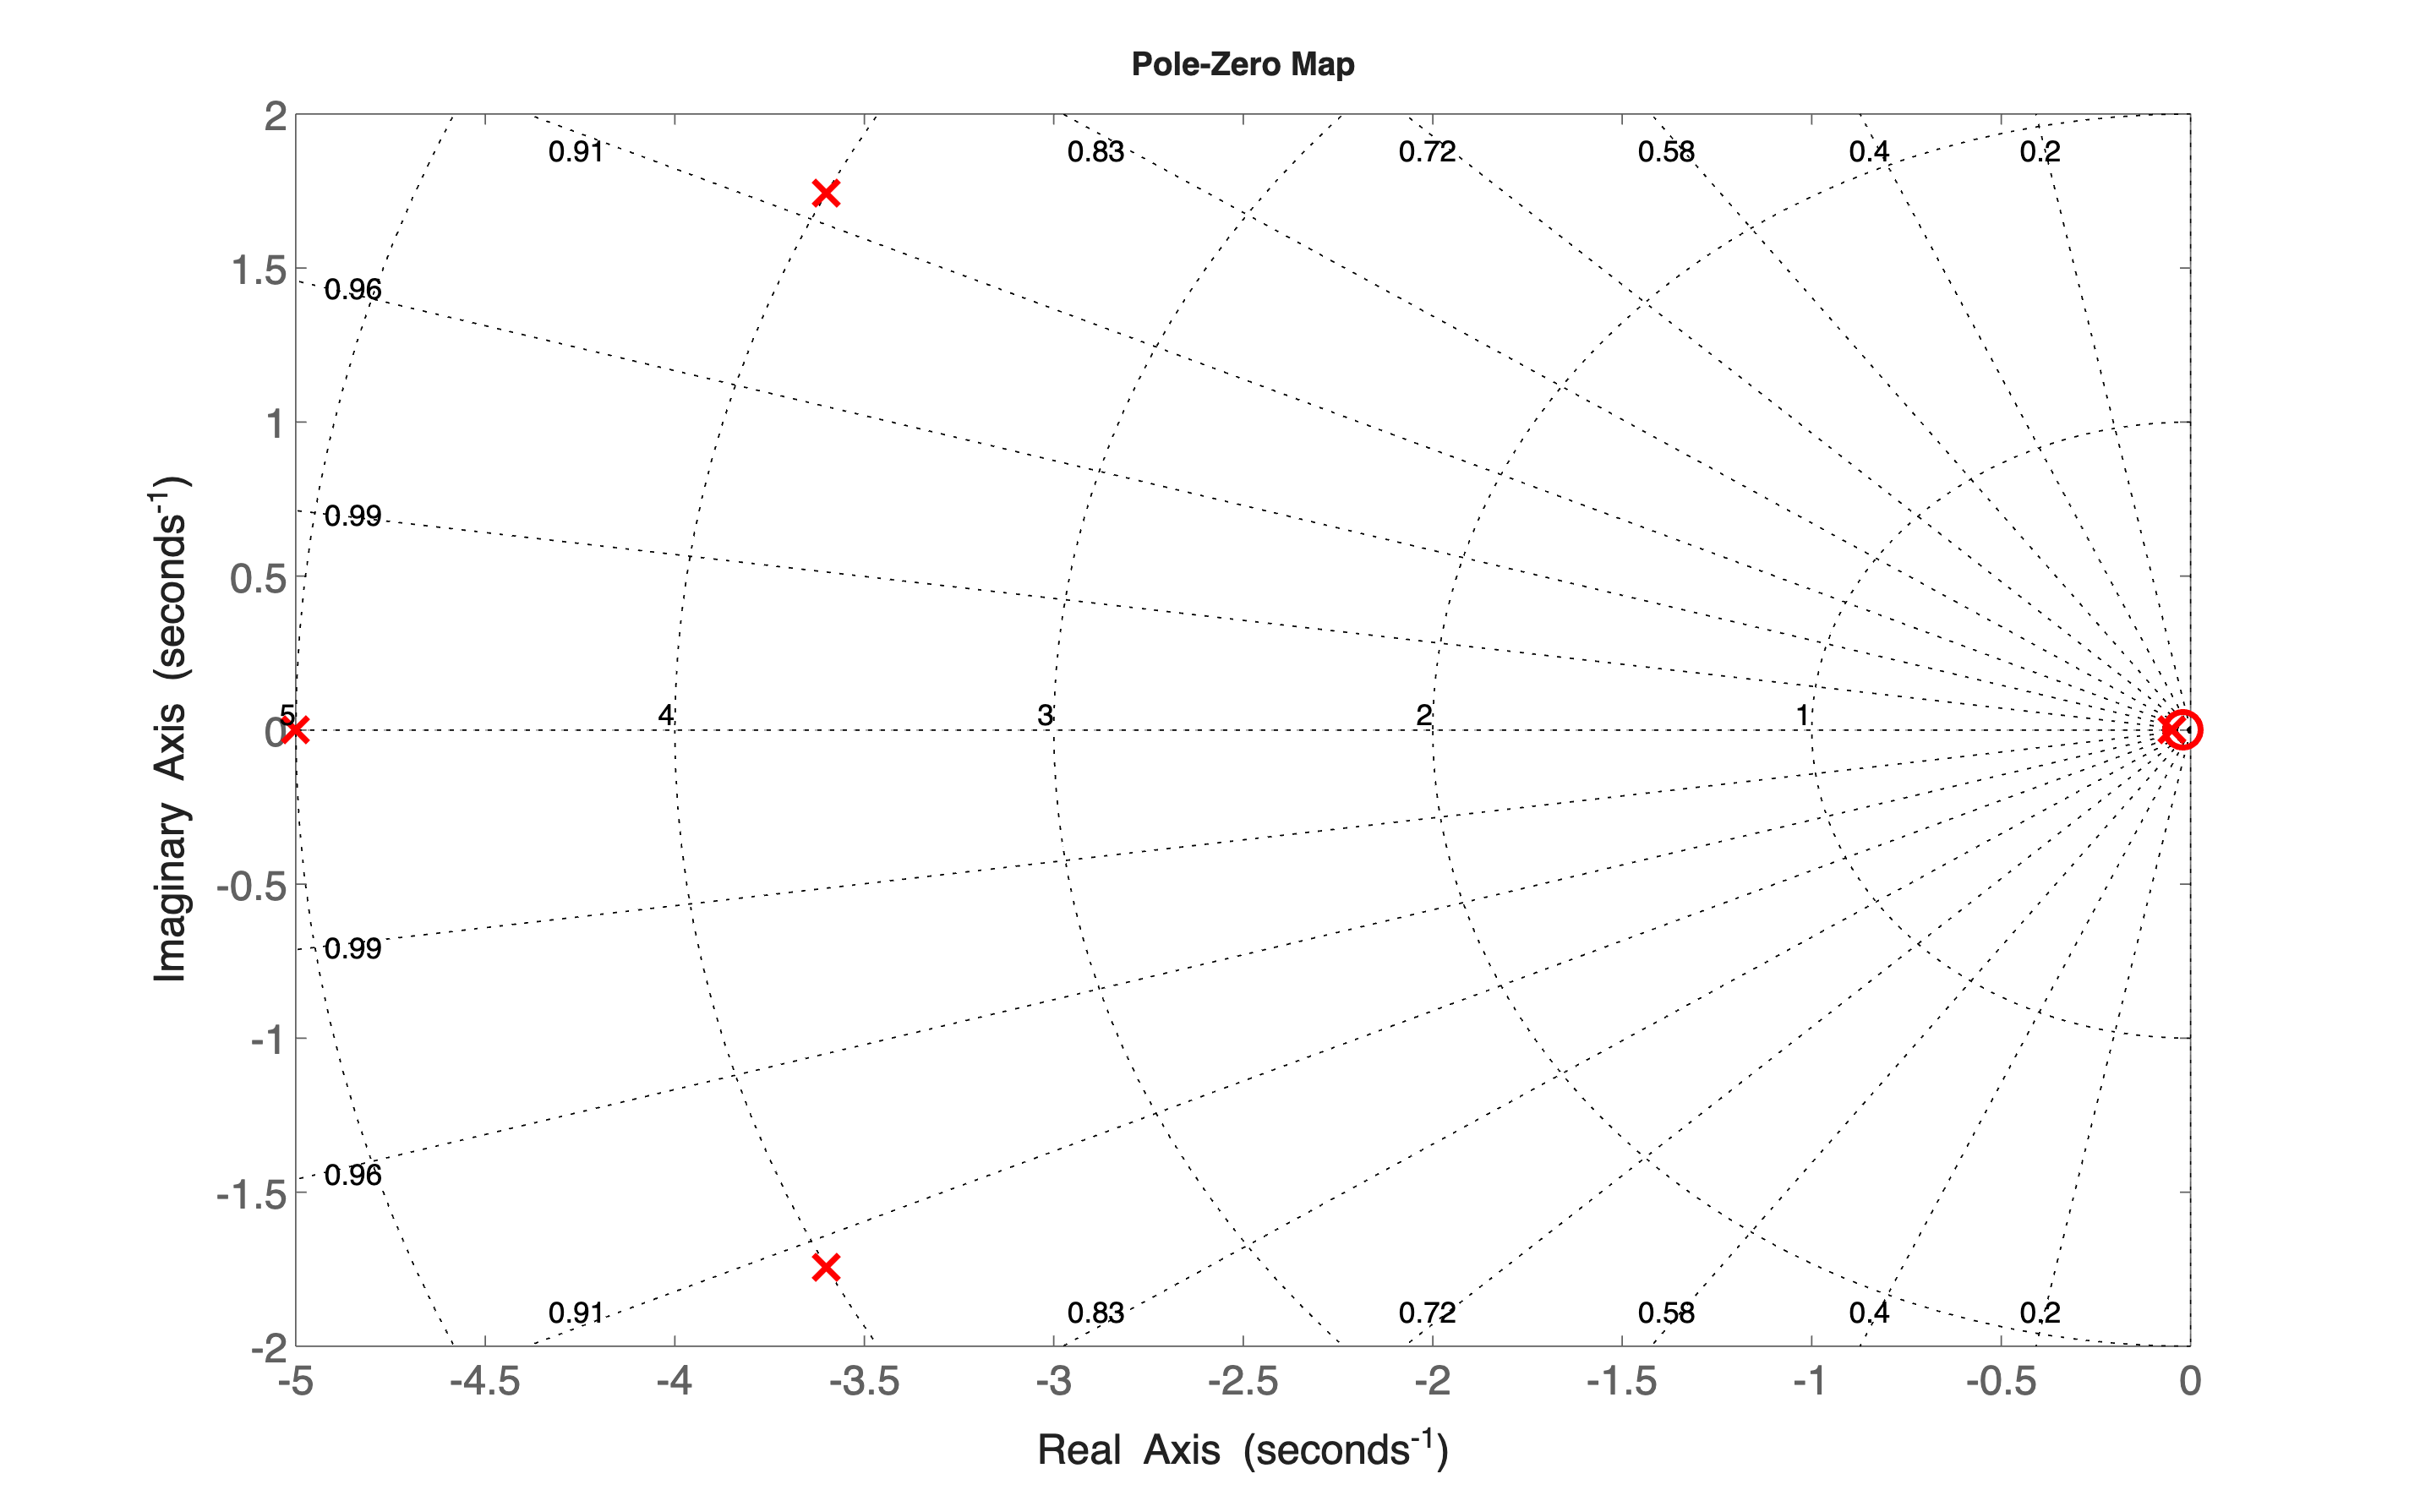

hf = figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
hPZP = pzplot(hf, G2s);
grid on
% get(hPZP)


% PZPlot properties:
% https://it.mathworks.com/help/ident/ref/controllib.chart.pzplot-properties.html
% https://it.mathworks.com/matlabcentral/answers/2173352-change-marker-colour-of-pzplot
%
hPZP.Responses(1).MarkerSize = 12;
hPZP.Responses(1).LineWidth = 2;
hPZP.Responses(1).Color = 'r';
% get(hPZP.AxesStyle(1))

% see 'doc pzplot' & 'doc pzoptions'
hPZP.AxesStyle(1).FontSize = 14;
hPZP.AxesStyle(1).GridColor = [0,0,0];

% hPZP.XLabel(1)
hPZP.XLabel(1).FontSize = 14;
hPZP.YLabel(1).FontSize = 14;

The pole closest to the origin is the dominant one. The zero close to the origin is also crucial to obtain a good apprimating model for the system.

#### The Dominant Pole Approximation

We may approximate the system $G_2(s)$ using a very simple model: the static gain, the real dominant pole and the zero:


$$G_{2\,\text{app}}(s) = 250 \cdot \frac{(1+50\,s)}{\left(1+ 20\,s \right)$$


tau2 = abs(1/p_G2s(1))

tau2 = 20

T2 = abs(1/z_G2s(1))

T2 = 50


G2sApproxV1 = tf(G2_staticGAIN, [tau2 1], "Name", "G2_apprV1") % without the zero


G2sApproxV1 =
 
    250
  --------
  20 s + 1
 
Name: G2_apprV1
Continuous-time transfer function.
Model Properties


G2sAPPROX = G2_staticGAIN * tf([T2  +1], [tau2 +1]) % with the zero


G2sAPPROX =
 
  12500 s + 250
  -------------
    20 s + 1
 
Continuous-time transfer function.
Model Properties


set(G2sAPPROX , "Name", "G2_apprV2")

Let's compare the step response of system $G_2(s)$ with the approximate models:

hf = figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
% let's create a blank figure

rpSP2 =stepplot(G2s,G2sApproxV1, G2sAPPROX, [0, 180]);
grid on; 
rpSP2

rpSP2 =   StepPlot with properties:

          Responses: [3×1 controllib.chart.response.StepResponse]
    Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

           TimeUnit: "seconds"
          Normalize: off

            Visible: on
         IOGrouping: "none"
       InputVisible: on
      OutputVisible: on

  Show all properties



% refer to https://it.mathworks.com/help/control/ug/customizing-response-plots-from-the-command-line.html
rpSP2.Characteristics(1).SettlingTime(1).Threshold = 0.01; % 1 %
rpSP2.Characteristics(1).SettlingTime(1).Visible = "on"; 
rpSP2.Characteristics(1).SteadyState(1).Visible = "on";
rpSP2.LegendVisible = "on";
rpSP2.LegendLocation = "best";

grid on; 
rpSP2.Responses

ans =   3×1 StepResponse array:

  StepResponse    (G2)
  StepResponse    (G2_apprV1)
  StepResponse    (G2_apprV2)


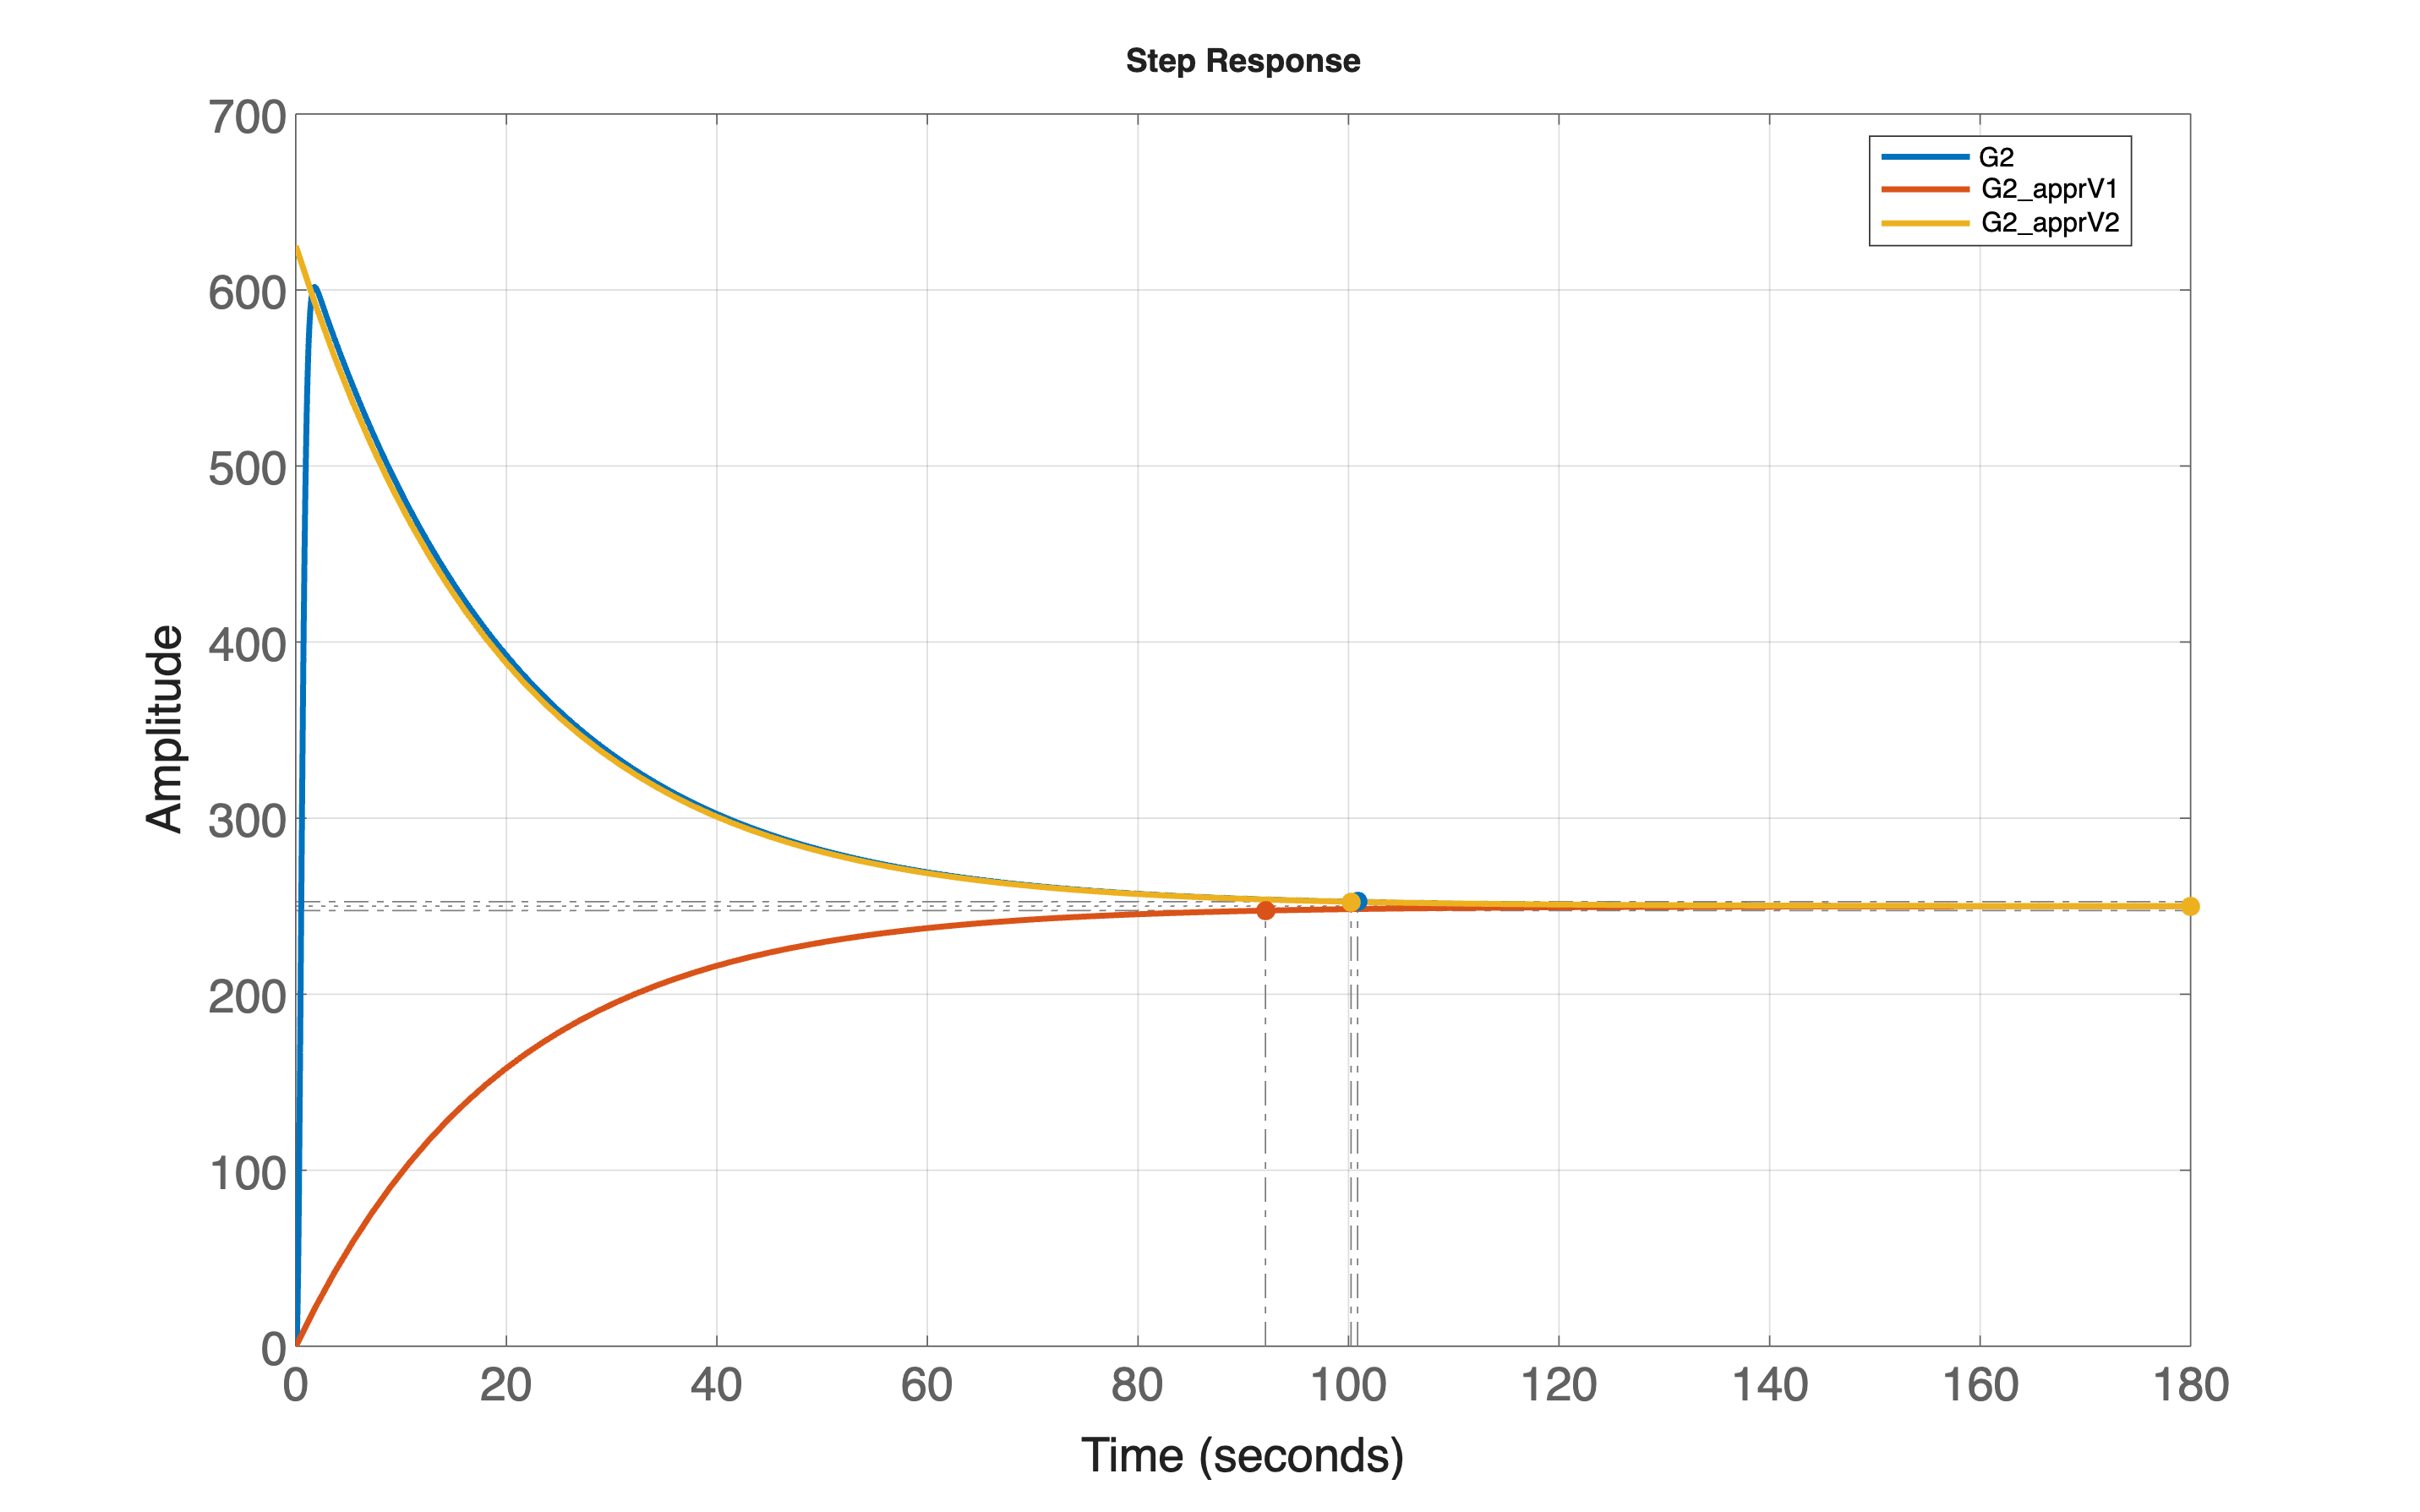


rpSP2.Responses(1).LineWidth = 2;
rpSP2.Responses(2).LineWidth = 2;
rpSP2.Responses(3).LineWidth = 2;

rpSP2.AxesStyle(1).FontSize=16;
rpSP2.XLabel(1).FontSize = 16;
rpSP2.YLabel(1).FontSize = 16;


G2info = stepinfo(G2s, "SettlingTimeThreshold", 0.01)

G2info = struct with fields:
         RiseTime: 0.3101
    TransientTime: 94.0374
     SettlingTime: 100.8657
      SettlingMin: 237.3440
      SettlingMax: 601.7330
        Overshoot: 140.6932
       Undershoot: 0
             Peak: 601.7330
         PeakTime: 1.7868



G2approx_V1_info = stepinfo(G2sApproxV1, "SettlingTimeThreshold", 0.01)

G2approx_V1_info = struct with fields:
         RiseTime: 43.9401
    TransientTime: 92.1034
     SettlingTime: 92.1034
      SettlingMin: 226.1252
      SettlingMax: 249.8348
        Overshoot: 0
       Undershoot: 0
             Peak: 249.8348
         PeakTime: 146.4444



G2approx_info = stepinfo(G2sAPPROX, "SettlingTimeThreshold", 0.01)

G2approx_info = struct with fields:
         RiseTime: 0
    TransientTime: 92.1034
     SettlingTime: 100.2160
      SettlingMin: 250.2478
      SettlingMax: 625
        Overshoot: 150
       Undershoot: 0
             Peak: 625
         PeakTime: 0


### Example 3 - Complex Dominant Poles

Consider the LTI system described by the transfer function


$$G_3(s) = \frac{250\,\left(1+\frac{s}{40} \right)}{\Big(1+\frac{s}{20}\Big)\left(1+\frac{s}{15} \right) \left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


clear
s = tf('s'); % the transfer function building helper

G3s = 250*(1+(s/40))/( (1+(s/20))*(1+s/15)*(1+(9/20)*s+s^2/16) ); % the transfer function

set(G3s, "Name", "G3");
G3_staticGAIN = dcgain(G3s) % the static gain of the LTI system

G3_staticGAIN = 250

p_G3s = sort(pole(G3s), 'ascend') % the poles of the transfer function

p_G3s =   -3.6000 - 1.7436i
  -3.6000 + 1.7436i
 -15.0000 + 0.0000i
 -20.0000 + 0.0000i



z_G3s = zero(G3s) % the zeros of the transfer function

z_G3s = -40

The poles and zeros configuration of the system is as follows

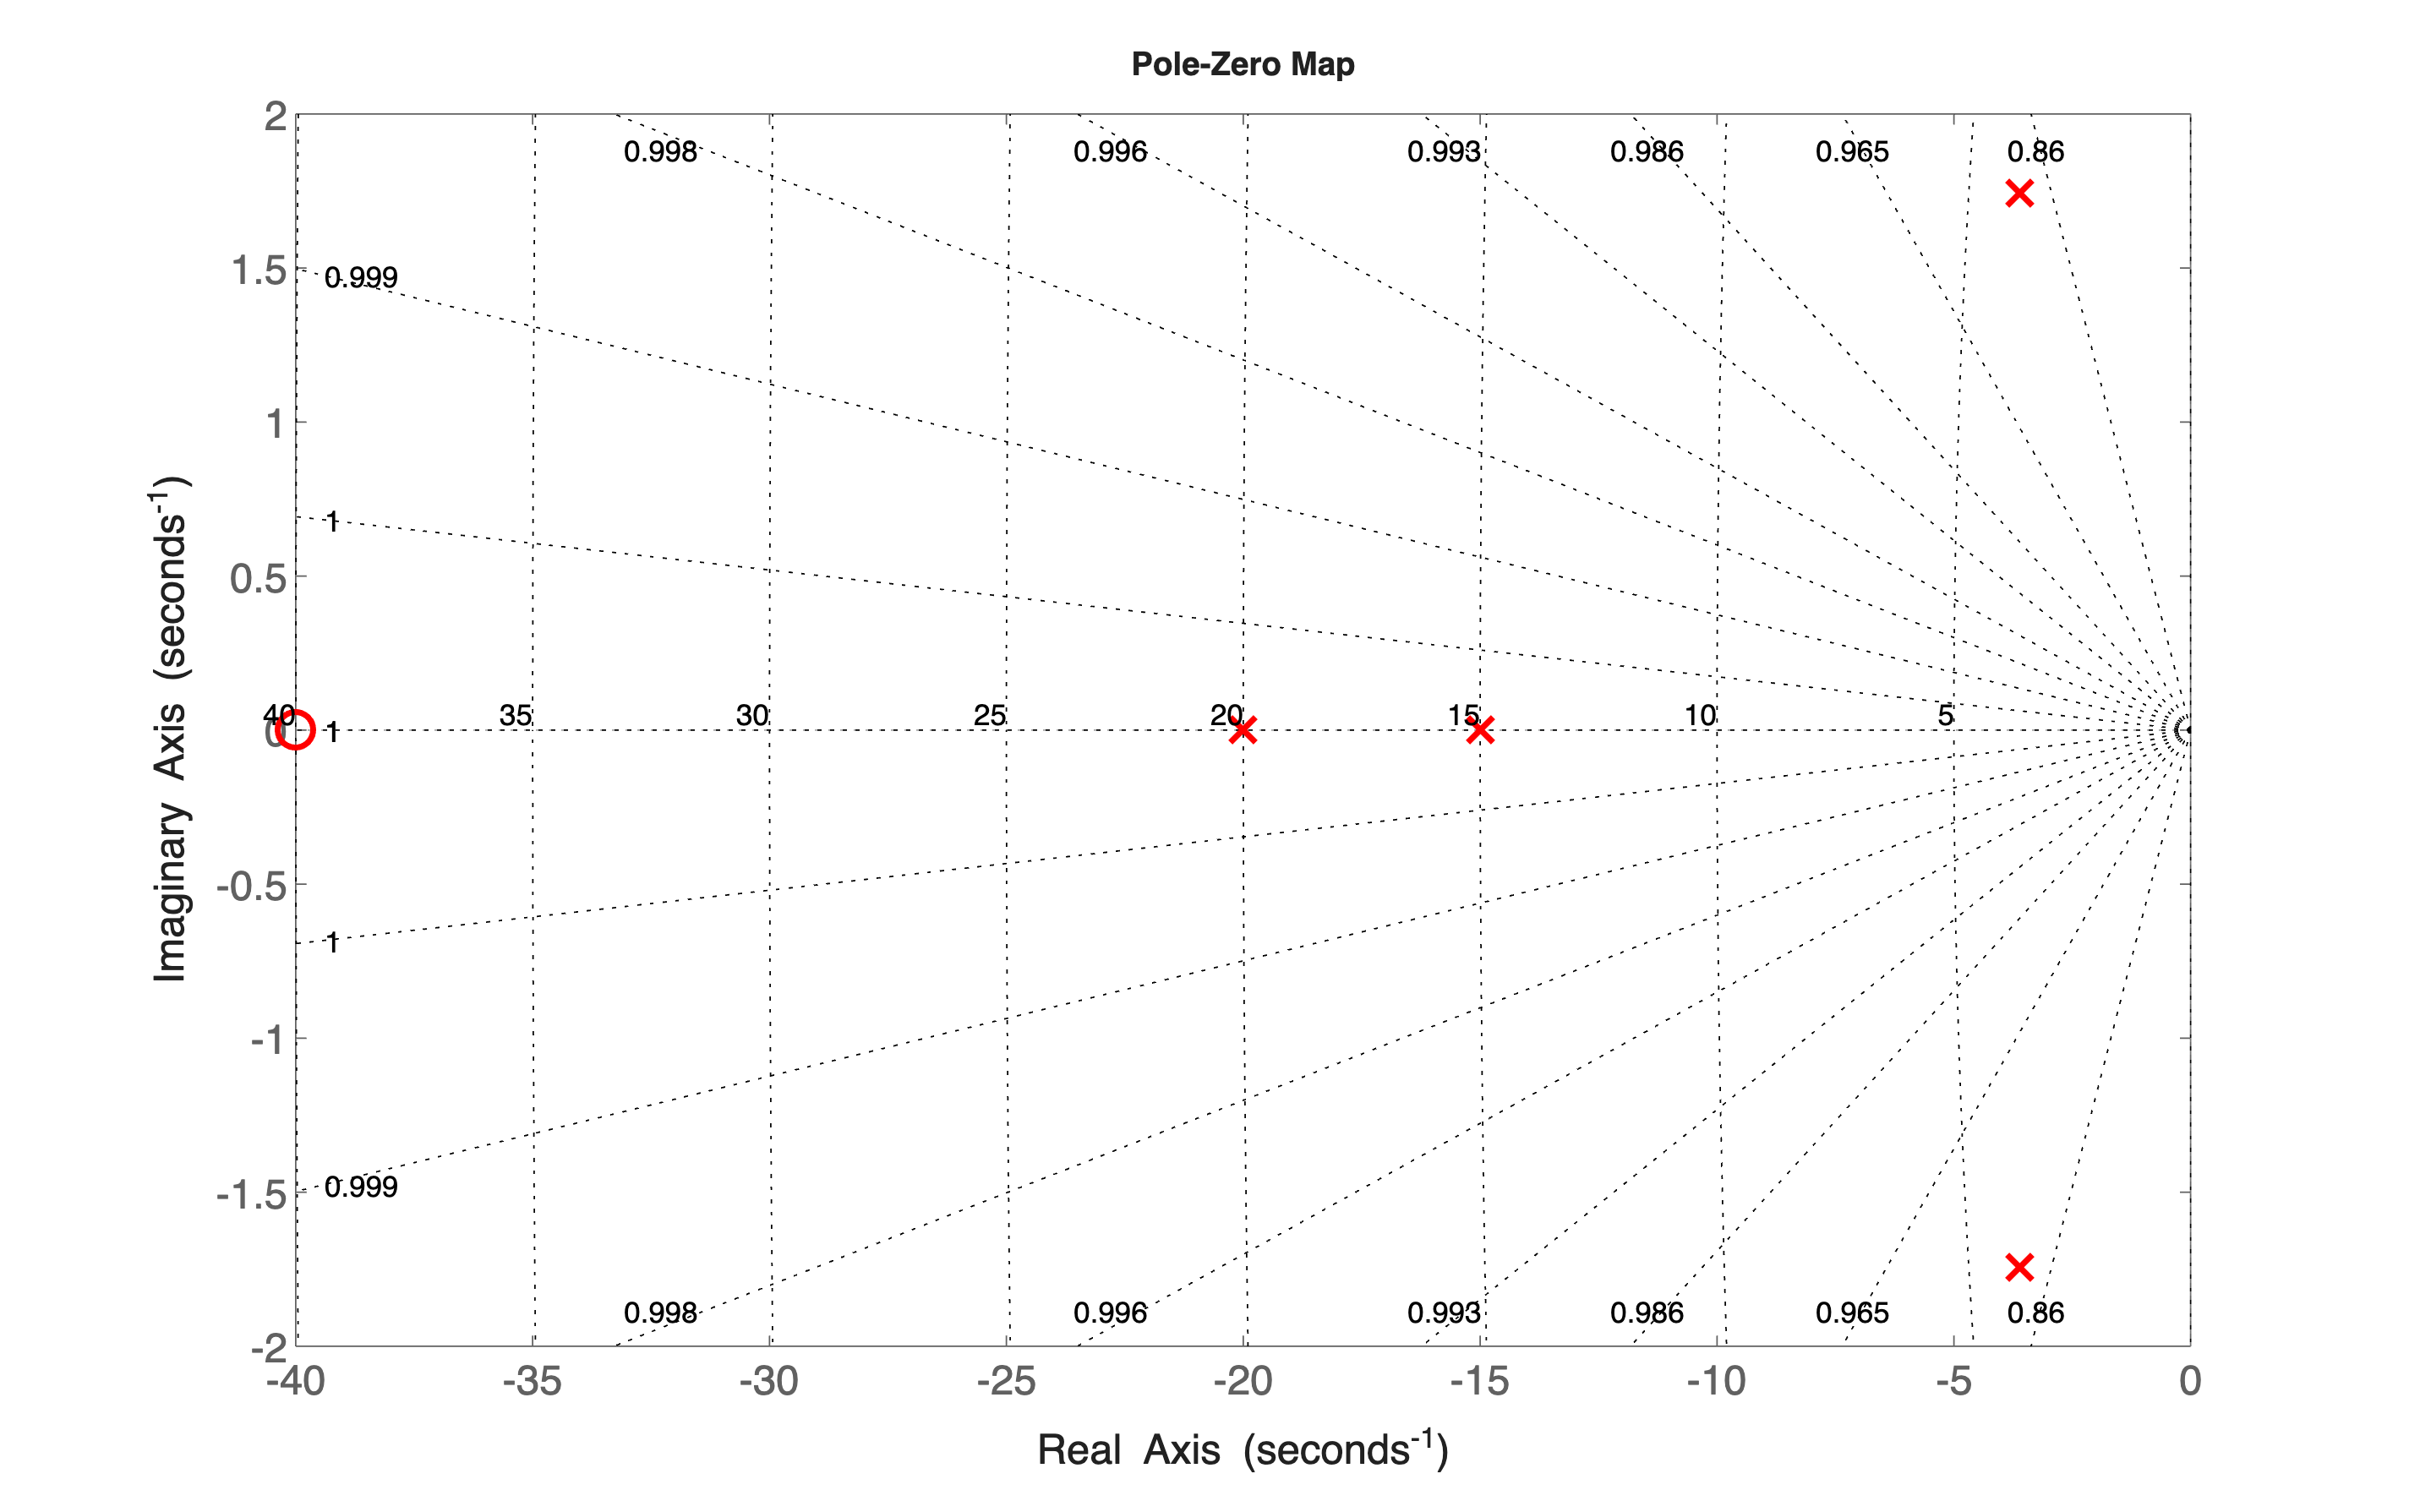

hf = figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
hPZP3 = pzplot(hf, G3s);
grid on
% get(hPZP)


% PZPlot properties:
% https://it.mathworks.com/help/ident/ref/controllib.chart.pzplot-properties.html
% https://it.mathworks.com/matlabcentral/answers/2173352-change-marker-colour-of-pzplot
%
hPZP3.Responses(1).MarkerSize = 12;
hPZP3.Responses(1).LineWidth = 2;
hPZP3.Responses(1).Color = 'r';
% get(hPZP.AxesStyle(1))

% see 'doc pzplot' & 'doc pzoptions'
hPZP3.AxesStyle(1).FontSize = 14;
hPZP3.AxesStyle(1).GridColor = [0,0,0];

% hPZP.XLabel(1)
hPZP3.XLabel(1).FontSize = 14;
hPZP3.YLabel(1).FontSize = 14;

The poles closest to the origin are the dominant ones. 

#### The Dominant Poles Approximation

We may approximate the system $G_3(s)$ using a very simple model: the static gain and the dominant poles


$$G_{3\,\text{app}}(s) = 250 \cdot \frac{1}{\left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


G3sAPPROX = 250*(1)/( (1+(9/20)*s+s^2/16) ); % the approximating tranfer function
set(G3sAPPROX, "Name", "G3_approx");

Let's compare the step response of system $G_3(s)$ with the approximate model:

hf = figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
% let's create a blank figure

rpSP3 = stepplot(G3s, G3sAPPROX, [0, 180]);
rpSP3

rpSP3 =   StepPlot with properties:

          Responses: [2×1 controllib.chart.response.StepResponse]
    Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

           TimeUnit: "seconds"
          Normalize: off

            Visible: on
         IOGrouping: "none"
       InputVisible: on
      OutputVisible: on

  Show all properties



% refer to https://it.mathworks.com/help/control/ug/customizing-response-plots-from-the-command-line.html
rpSP3.Characteristics(1).SettlingTime(1).Threshold = 0.01; % 1 %
rpSP3.Characteristics(1).SettlingTime(1).Visible = "on"; 
rpSP3.Characteristics(1).SteadyState(1).Visible = "on";
rpSP3.LegendVisible = "on";
rpSP3.LegendLocation = "best";

grid on; 
rpSP3.Responses

ans =   2×1 StepResponse array:

  StepResponse    (G3)
  StepResponse    (G3_approx)


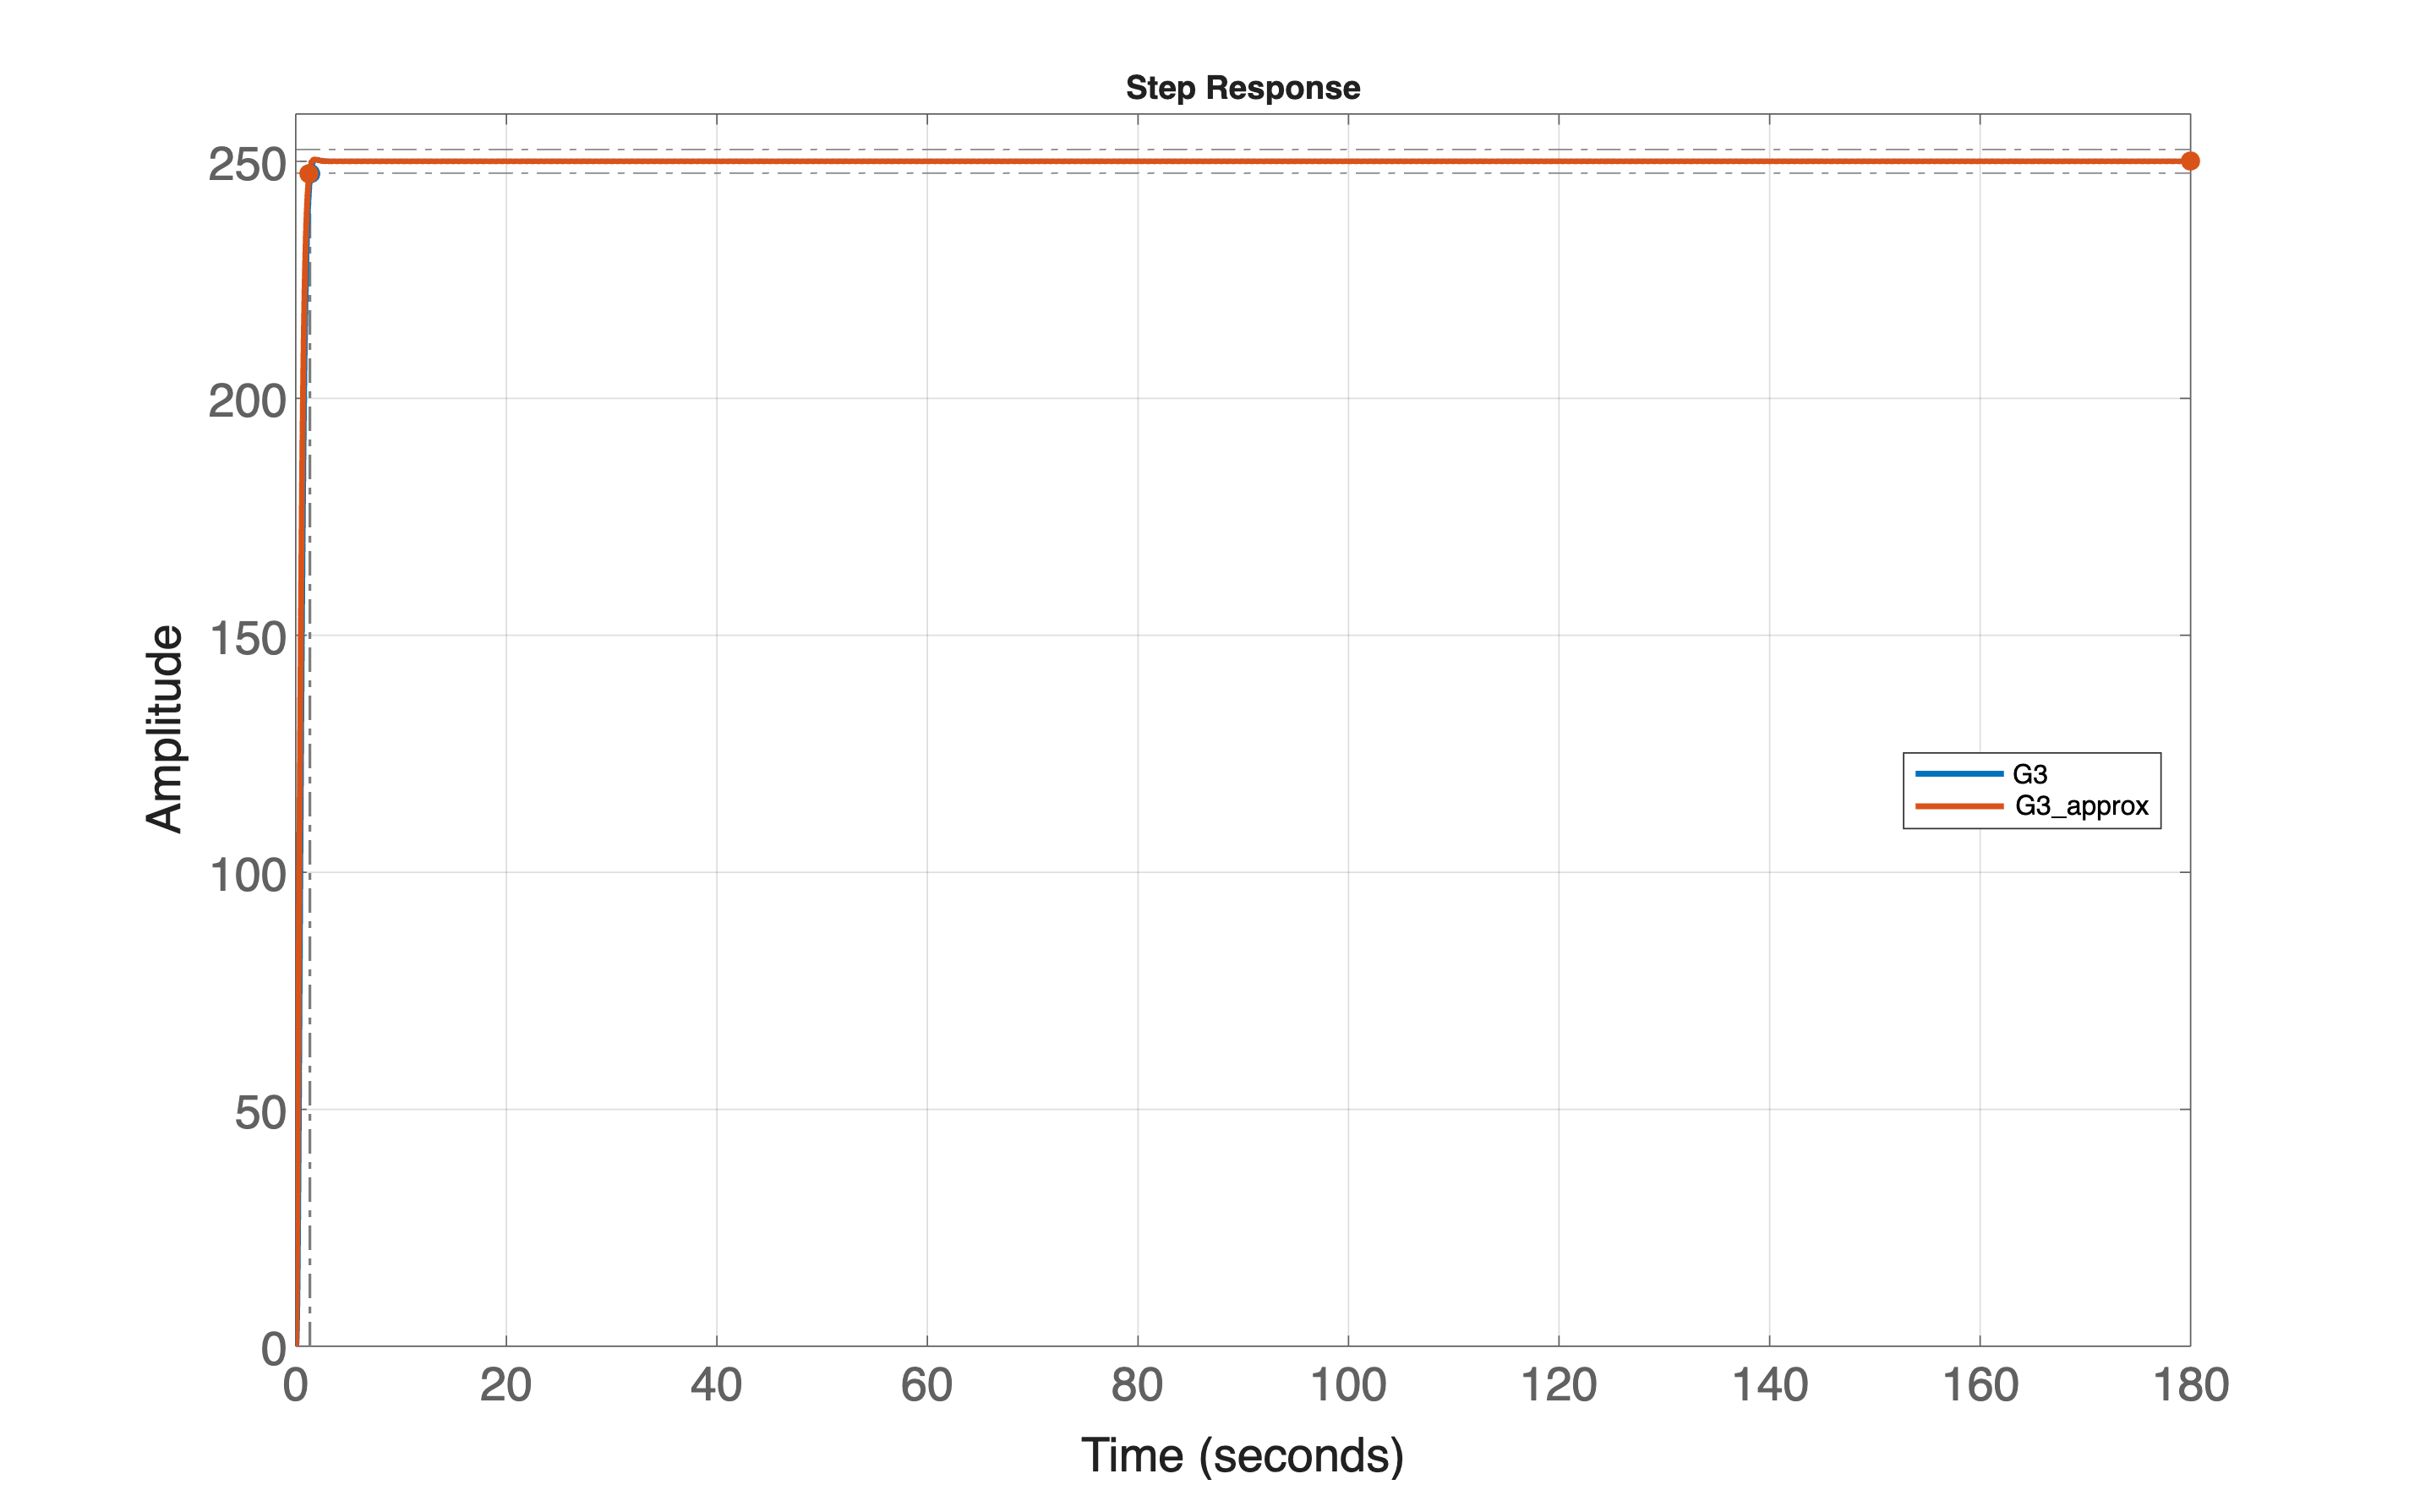


rpSP3.Responses(1).LineWidth = 2;
rpSP3.Responses(2).LineWidth = 2;
ylim([0, 260]);
rpSP3.AxesStyle(1).FontSize=16;
rpSP3.XLabel(1).FontSize = 16;
rpSP3.YLabel(1).FontSize = 16;


G3info = stepinfo(G3s, "SettlingTimeThreshold", 0.01)

G3info = struct with fields:
         RiseTime: 0.7496
    TransientTime: 1.3922
     SettlingTime: 1.3922
      SettlingMin: 225.4575
      SettlingMax: 250.3549
        Overshoot: 0.1420
       Undershoot: 0
             Peak: 250.3549
         PeakTime: 1.9188



G3approx_info = stepinfo(G3sAPPROX, "SettlingTimeThreshold", 0.01)

G3approx_info = struct with fields:
         RiseTime: 0.7209
    TransientTime: 1.2819
     SettlingTime: 1.2819
      SettlingMin: 225.6020
      SettlingMax: 250.3809
        Overshoot: 0.1524
       Undershoot: 0
             Peak: 250.3809
         PeakTime: 1.8037


### Final Example - A Set of Dominant Poles and Zeros

Consider the LTI system described by the transfer function


$$G_4(s) = \frac{250\,\left(1+\frac{4}{5}\,s+\frac{s^2}{4} \right)\,\left(1+\frac{s}{200}\right)}{\Big(1+\frac{s}{20}\Big)\left(1+\frac{s}{3} \right) \left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


clear
s = tf('s'); % the transfer function building helper

G4s = 250*(1+0.8*s+(s^2/4))*(1+s/200)/( (1+(s/20))*(1+s/3)*(1+(9/20)*s+s^2/16) ); % the tranfer function
set(G4s, "Name", "G4");

G4_staticGAIN = dcgain(G4s) % the static gain of the LTI system

G4_staticGAIN = 250

p_G4s = sort(pole(G4s), 'ascend') % the poles of the transfer function

p_G4s =   -3.0000 + 0.0000i
  -3.6000 - 1.7436i
  -3.6000 + 1.7436i
 -20.0000 + 0.0000i



z_G4s = sort(zero(G4s), 'ascend') % the zeros of the transfer function

z_G4s = 1.0e+02 *

  -0.0160 - 0.0120i
  -0.0160 + 0.0120i
  -2.0000 + 0.0000i


The poles and zeros configuration of the system is as follows

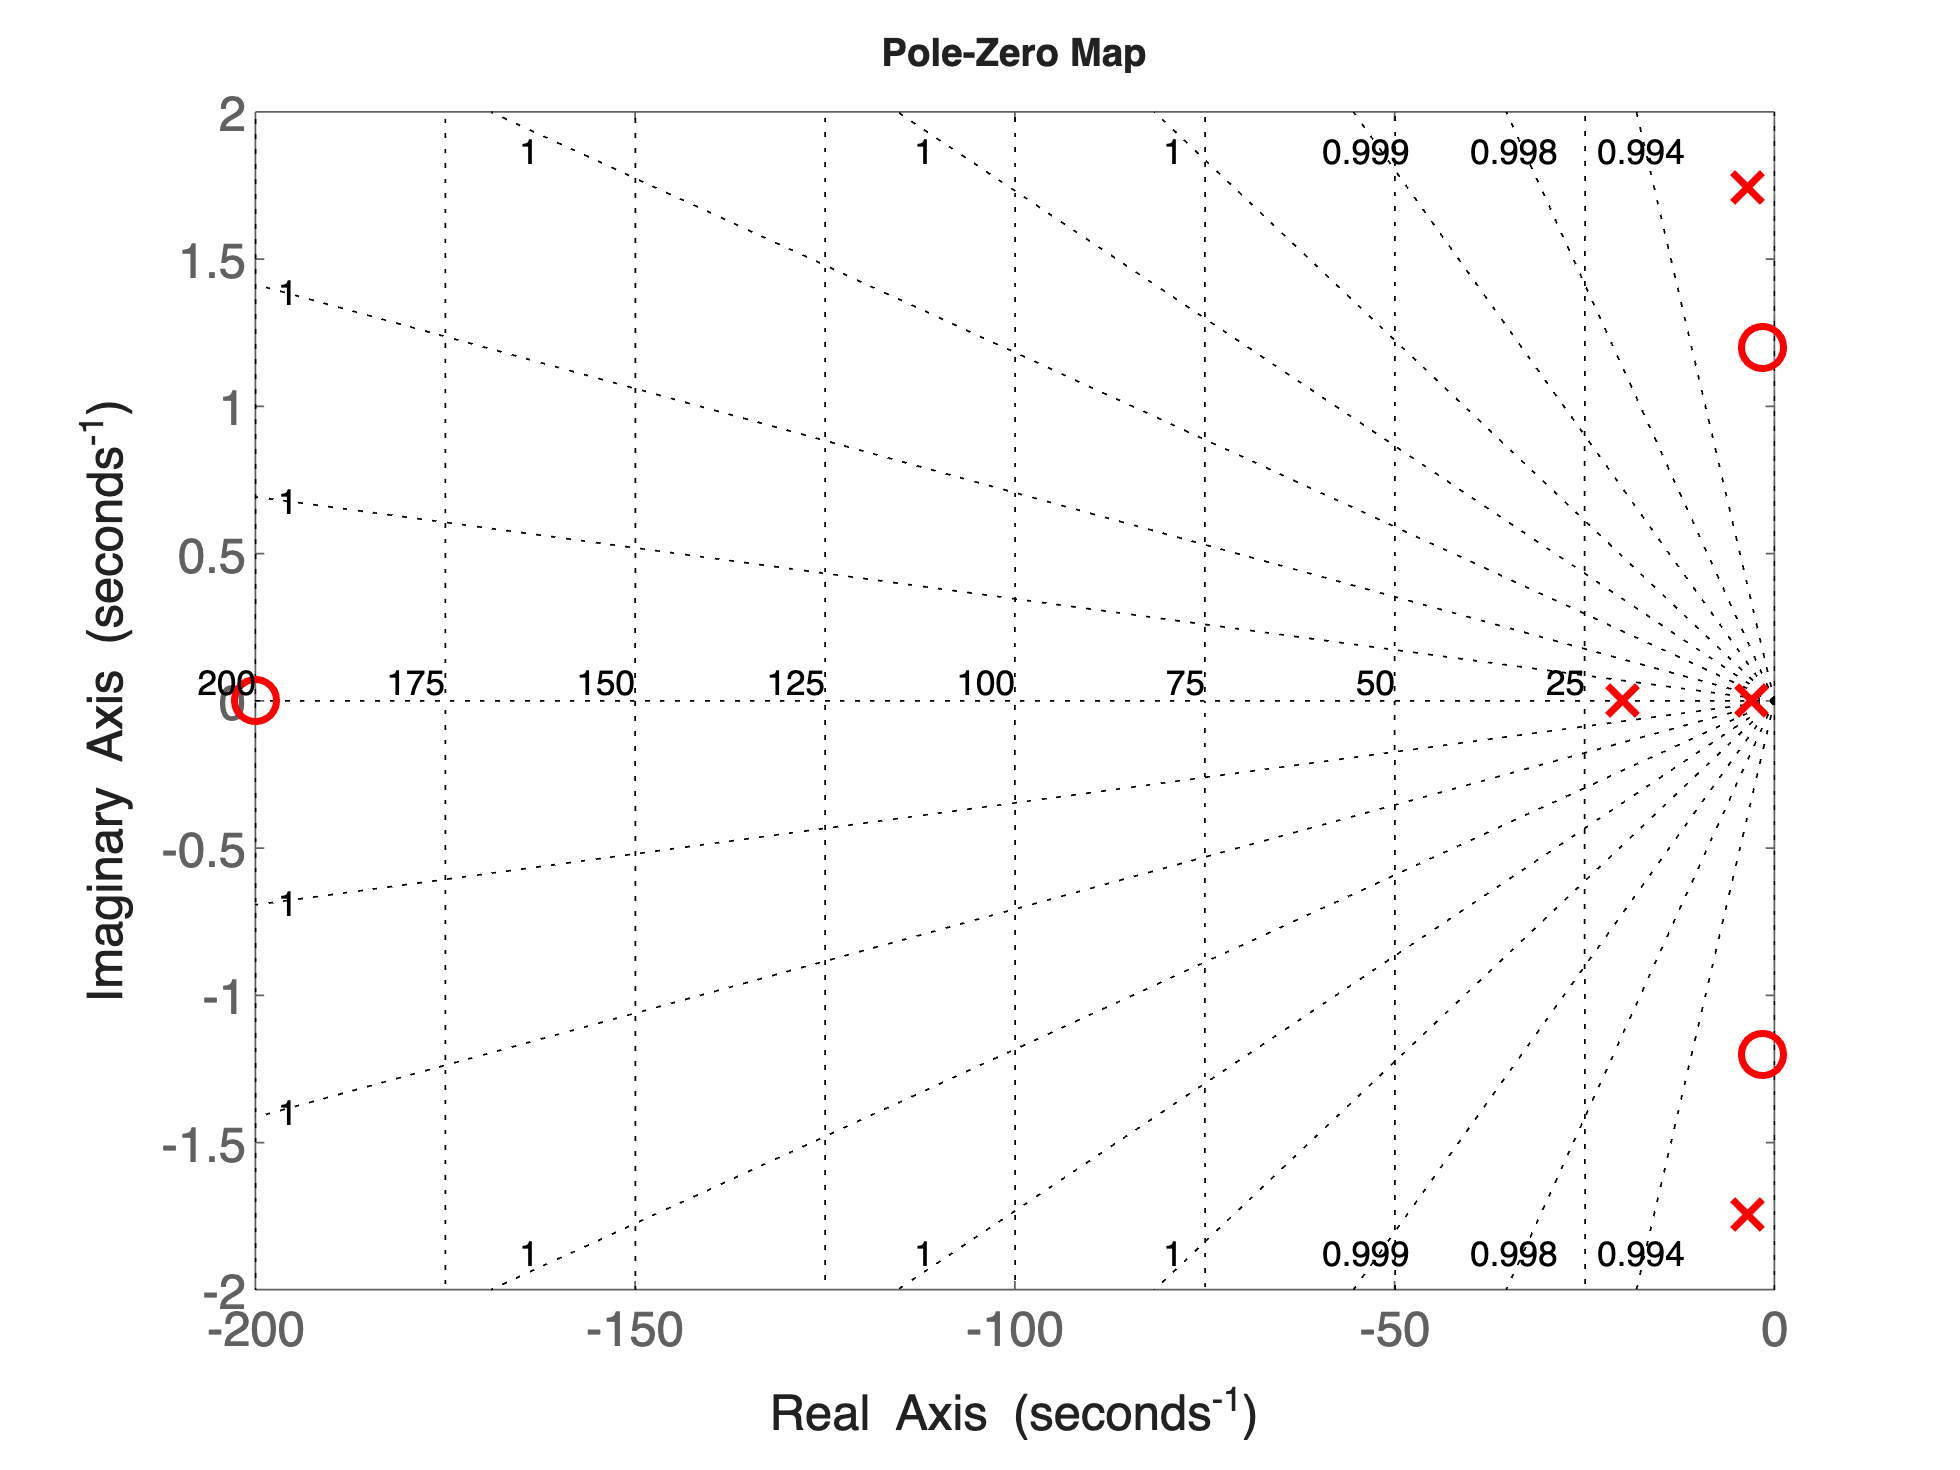

figure;
hPZP4 = pzplot(G4s);
grid on

% get(hPZP)


% PZPlot properties:
% https://it.mathworks.com/help/ident/ref/controllib.chart.pzplot-properties.html
% https://it.mathworks.com/matlabcentral/answers/2173352-change-marker-colour-of-pzplot
%
hPZP4.Responses(1).MarkerSize = 12;
hPZP4.Responses(1).LineWidth = 2;
hPZP4.Responses(1).Color = 'r';
% get(hPZP.AxesStyle(1))

% see 'doc pzplot' & 'doc pzoptions'
hPZP4.AxesStyle(1).FontSize = 14;
hPZP4.AxesStyle(1).GridColor = [0,0,0];

% hPZP.XLabel(1)
hPZP4.XLabel(1).FontSize = 14;
hPZP4.YLabel(1).FontSize = 14;

The poles closest to the origin are the dominant ones.  This time, there are two complex poles and one real pole close to the origin (with real parts very close to each other - we cannot neglect any of the poles in question). In addition, the pair of complex zeros must also be considered.

#### The Dominant Poles Approximation

We may approximate the system $G_4(s)$ using a very simple model: the static gain and the dominant poles


$$G_{4\,\text{app}}(s) = 250 \cdot \frac{\left(1+\frac{4}{5}\,s+\frac{s^2}{4} \right)}{\left(1+\frac{s}{3} \right) \left(1+\frac{9}{20}s +\frac{s^2}{16}\right)}$$


G4sAPPROX = 250*(1+0.8*s+(s^2/4))/( (1+s/3)*(1+(9/20)*s+s^2/16) ); % the approximating tranfer function
set(G4sAPPROX, "Name", "G4_approx");

Let's compare the step response of system $G_3(s)$ with the approximate model:

hf = figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.9, 0.9]);
% let's create a blank figure

rpSP4 = stepplot(G4s, G4sAPPROX, [0, 180]);
grid on; zoom on;
rpSP4

rpSP4 =   StepPlot with properties:

          Responses: [2×1 controllib.chart.response.StepResponse]
    Characteristics: [1×1 controllib.chart.options.CharacteristicsManager]

           TimeUnit: "seconds"
          Normalize: off

            Visible: on
         IOGrouping: "none"
       InputVisible: on
      OutputVisible: on

  Show all properties



% refer to https://it.mathworks.com/help/control/ug/customizing-response-plots-from-the-command-line.html
rpSP4.Characteristics(1).SettlingTime(1).Threshold = 0.01; % 1 %
rpSP4.Characteristics(1).SettlingTime(1).Visible = "on"; 
rpSP4.Characteristics(1).SteadyState(1).Visible = "on";
rpSP4.LegendVisible = "on";
rpSP4.LegendLocation = "best";

rpSP4.Responses

ans =   2×1 StepResponse array:

  StepResponse    (G4)
  StepResponse    (G4_approx)


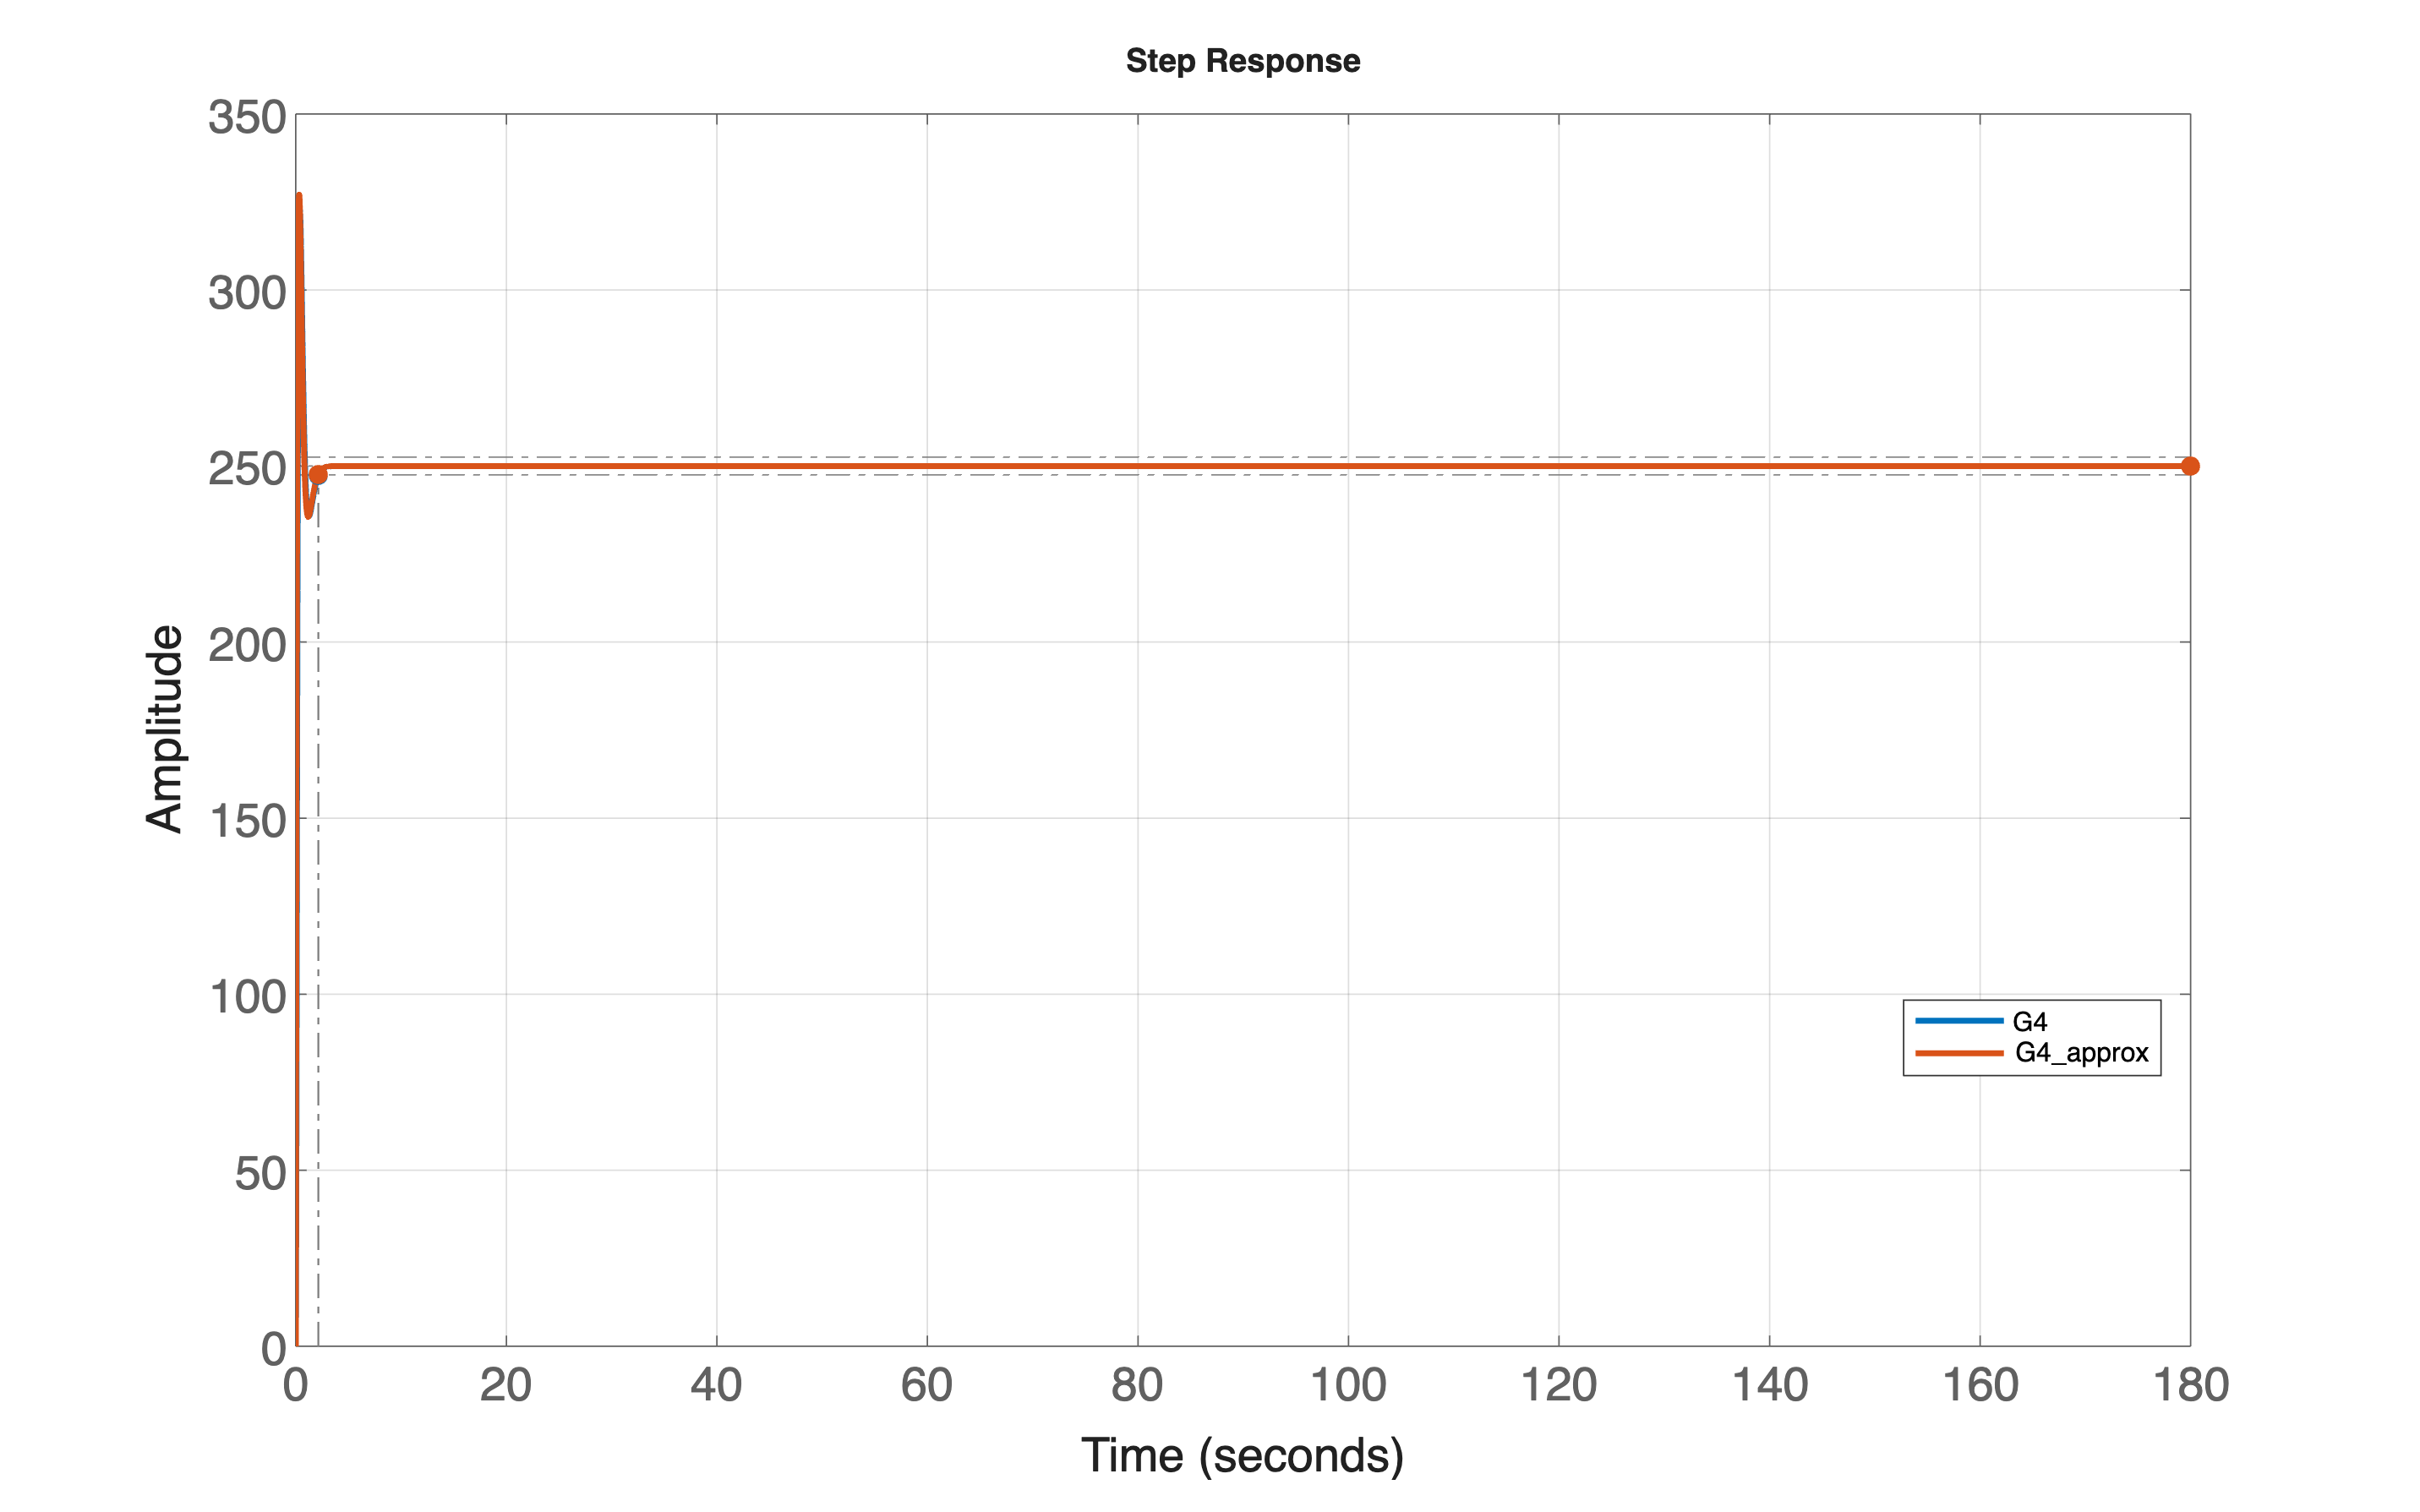


rpSP4.Responses(1).LineWidth = 2;
rpSP4.Responses(2).LineWidth = 2;
%ylim([0, 260]);
rpSP4.AxesStyle(1).FontSize=16;
rpSP4.XLabel(1).FontSize = 16;
rpSP4.YLabel(1).FontSize = 16;


G4info = stepinfo(G4s, "SettlingTimeThreshold", 0.01)

G4info = struct with fields:
         RiseTime: 0.1341
    TransientTime: 2.1588
     SettlingTime: 2.1588
      SettlingMin: 232.3190
      SettlingMax: 323.0583
        Overshoot: 29.2233
       Undershoot: 0
             Peak: 323.0583
         PeakTime: 0.3838



G4approx_info = stepinfo(G4sAPPROX, "SettlingTimeThreshold", 0.01)

G4approx_info = struct with fields:
         RiseTime: 0.1012
    TransientTime: 2.1106
     SettlingTime: 2.1106
      SettlingMin: 235.5384
      SettlingMax: 327.2357
        Overshoot: 30.8943
       Undershoot: 0
             Peak: 327.2357
         PeakTime: 0.3224
